# Autoencoder Notebook: 

## I. Generating synthetic EEG:

### 1. Spike to EEG model using Stochastic Harmonic Oscillator

clear;clc;

% Parameter setup and model invocation

param.N_neur = 256; % Number of "neurons" (binary units)
param.N_F = 5; % Number of latent fields hₘ(t)
% param.tau_F = [0.001 0.01 0.1 1]; % Time constants (in seconds) for each OU field
param.T = 120; % Total simulation time (in seconds)
param.dt = 1e-3;
fs_orig = 1/param.dt;
fs_new  = 500;  

param.latent_type = 'SDHO'; % or OU for Ornstein-Uhlenbeck
param.f_peak = [2, 5, 10, 20, 40];
param.zeta_val = [0.05, 0.051, 0.06, 0.1, 0.08];

% param.fixJ_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F); % ordered_J_if; %
param.eta_val = 3;
param.eps_val = 4; % 1 or 2.67 *param.eta_val previous, "Inverse temperature" and silence bias
[s_i, param, h_f] = sampleMorrellModel(param);

[MorrellModel] Using SDHO latent process.


#### 1.1.1 Getting the number of significant components based on Merchenko-Pastur threshold

% Marchenko–Pastur threshold
eig_vals = eig(cov(s_i'));
[N, T] = size(s_i);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 37 PCs


## 1.1.1 Plotting the latent variables, spikes, histogram for spiking rate

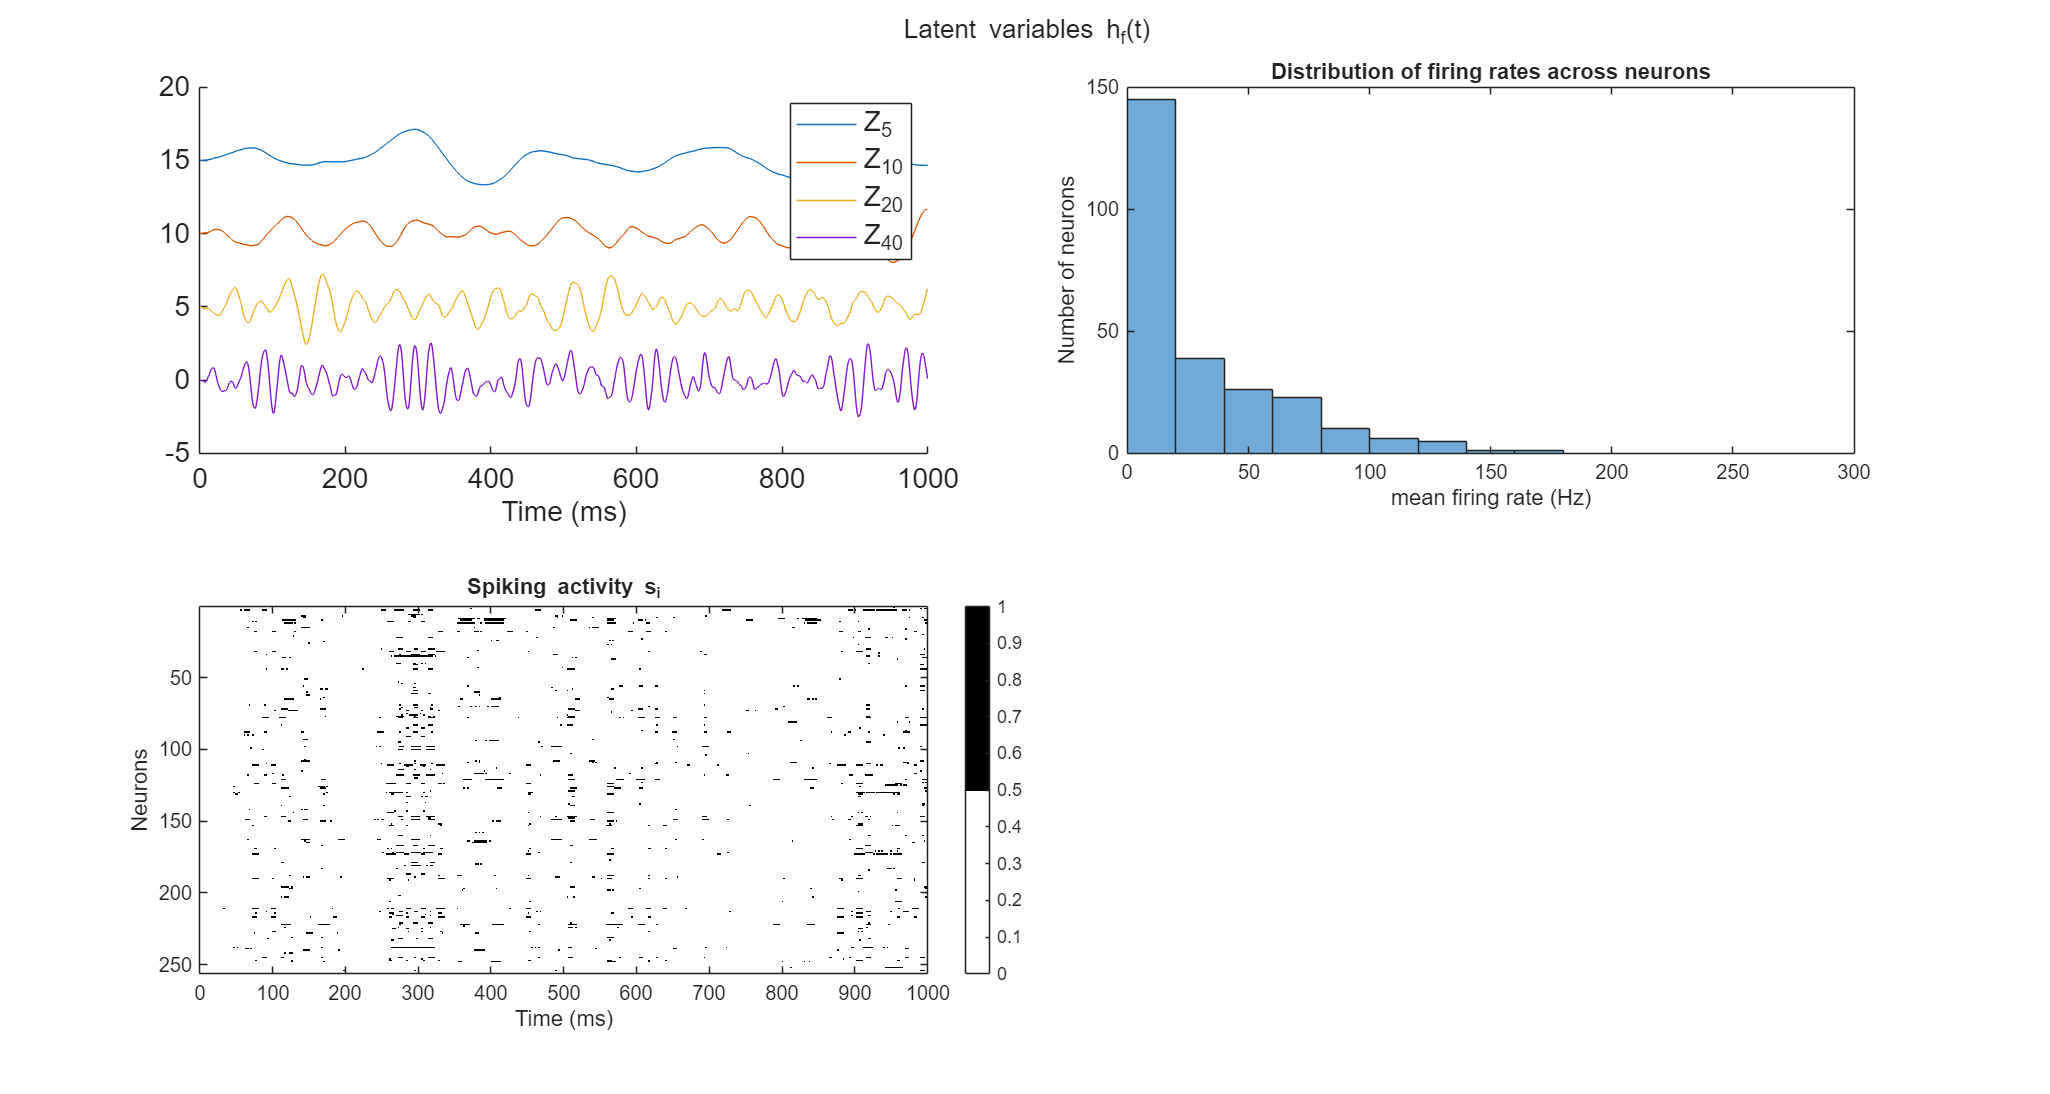

mean_rate_Hz = mean(s_i,2) / param.dt;

time_ms = (0:T-1) * param.dt * 1000; % time in milliseconds
map = [1 1 1 
    0 0 0];
figure('Position',[50 50 1500 800])
tiledlayout(2,2)
% Latent variables
nexttile
h_f_colors = lines(param.N_F);
% y_limits = [-4 4];  % force consistent y-scale
offset = 5;
time_hf_ds = time_ms * fs_new/fs_orig;

hold on
for f = 1:param.N_F
    % nexttile
    plot(time_ms,h_f(:, f)+(param.N_F-f)*offset, 'Color', h_f_colors(f,:));
    xlim([0 1000]);
  
end
xlabel('Time (ms)');
legend(sprintf('Z_{%d}', param.f_peak(1)),...
    sprintf('Z_{%d}', param.f_peak(2)),...
    sprintf('Z_{%d}', param.f_peak(3)),...
    sprintf('Z_{%d}', param.f_peak(4)));  
hold off


sgtitle('Latent variables h_f(t)'); % overall title
set(findall(gcf,'-property','FontSize'),'FontSize',14);
nexttile
histogram(mean_rate_Hz);
xlim([0 300]);
% set(gca, 'YScale', 'log'); 
xlabel('mean firing rate (Hz)');
ylabel('Number of neurons');
title('Distribution of firing rates across neurons');

% Spiking activity
nexttile
imagesc(time_ms, 1:param.N_neur, s_i)
xlabel('Time (ms)')
ylabel('Neurons')
xlim([0 1000]);   % show first 500 ms
title('Spiking activity s_i')
colormap(map); 
colorbar;

#### 1.1.2 Downsampling

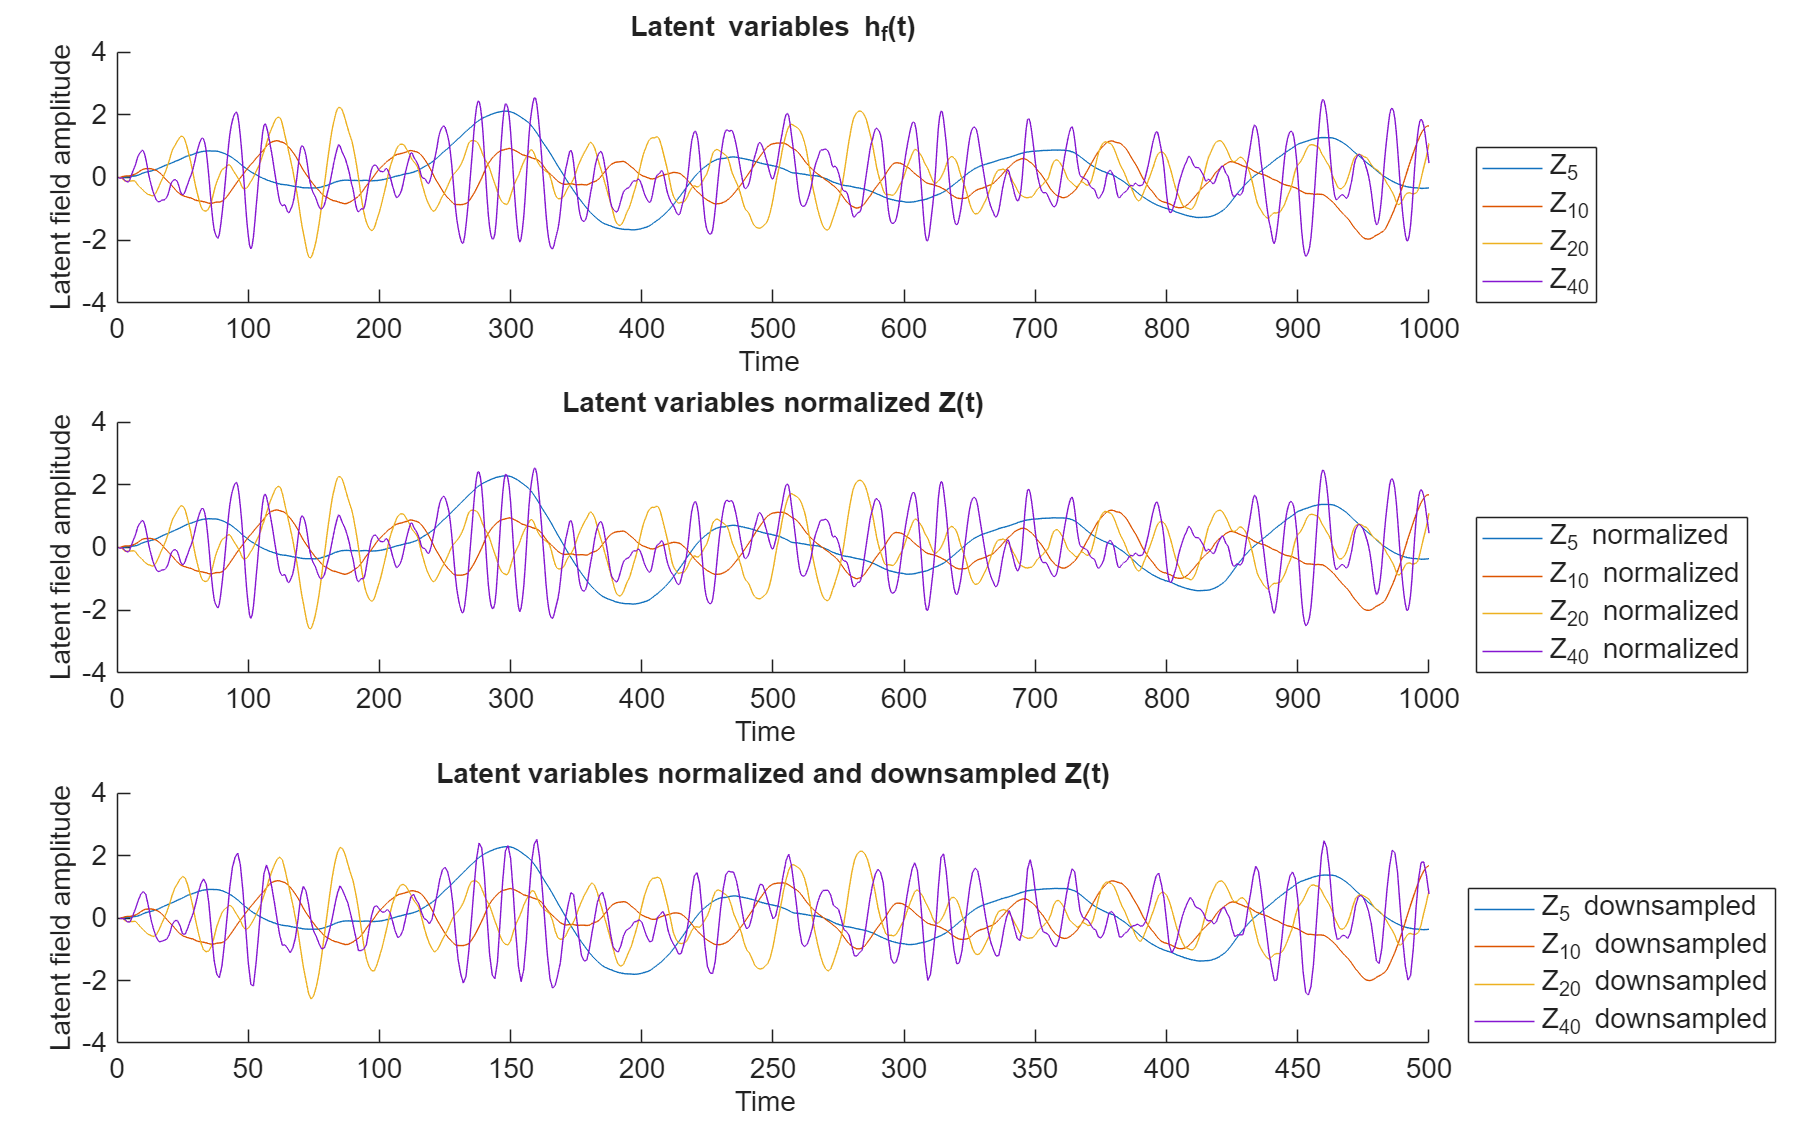


% --- 2) Resample latent fields (time x N_F) ---
[T_hf, N_F] = size(h_f);
fs_orig = 1/param.dt;
fs_new  = 500;   
h_f_ds = zeros(ceil(T_hf * fs_new / fs_orig), N_F);
for fidx = 1:N_F
    yhf = resample(double(h_f(:, fidx)), fs_new, fs_orig); % col vector
    h_f_ds(1:length(yhf), fidx) = yhf;
end
h_f_ds = h_f_ds(1:length(yhf), :);  % enforce exact truncation (all columns same length)

% Normalize latent variables by their variance (per column)

h_f_normalized = h_f ./ std(h_f, 0, 1);  % Time × N_F
h_f_normalized_ds = h_f_ds ./ std(h_f_ds, 0, 1);  % Time × N_F

figure('Position',[50 50 1200 750])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);

nexttile
hold on;
for f=1:param.N_F
    plot(h_f(:, f), 'Color', h_f_colors(f, :),'DisplayName', [sprintf('Z_{%d}', param.f_peak(f))]);
end
xlabel('Time ')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);
ylim([-4 4]);
legend( 'Show', 'Location', 'southeastoutside');
hold off;

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_normalized(:, f), 'Color', h_f_colors(f, :),'DisplayName', [sprintf('Z_{%d} normalized', param.f_peak(f))]);
end
xlabel('Time  ')
ylabel('Latent field amplitude')
title('Latent variables normalized Z(t)')
xlim([0 1000]);
ylim([-4 4]);
legend( 'Show','Location', 'southeastoutside');
hold off;

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_normalized_ds(:, f), 'Color', h_f_colors(f, :),'DisplayName', [sprintf('Z_{%d} downsampled', param.f_peak(f))]);
end
xlabel('Time  ')
ylabel('Latent field amplitude')
title('Latent variables normalized and downsampled Z(t)')
xlim([0 1000*fs_new/fs_orig]);
ylim([-4 4]);
legend( 'Show','Location', 'southeastoutside');
hold off;

set(findall(gcf,'-property','FontSize'),'FontSize',14);

## 1.1.3 Review paper Panel A

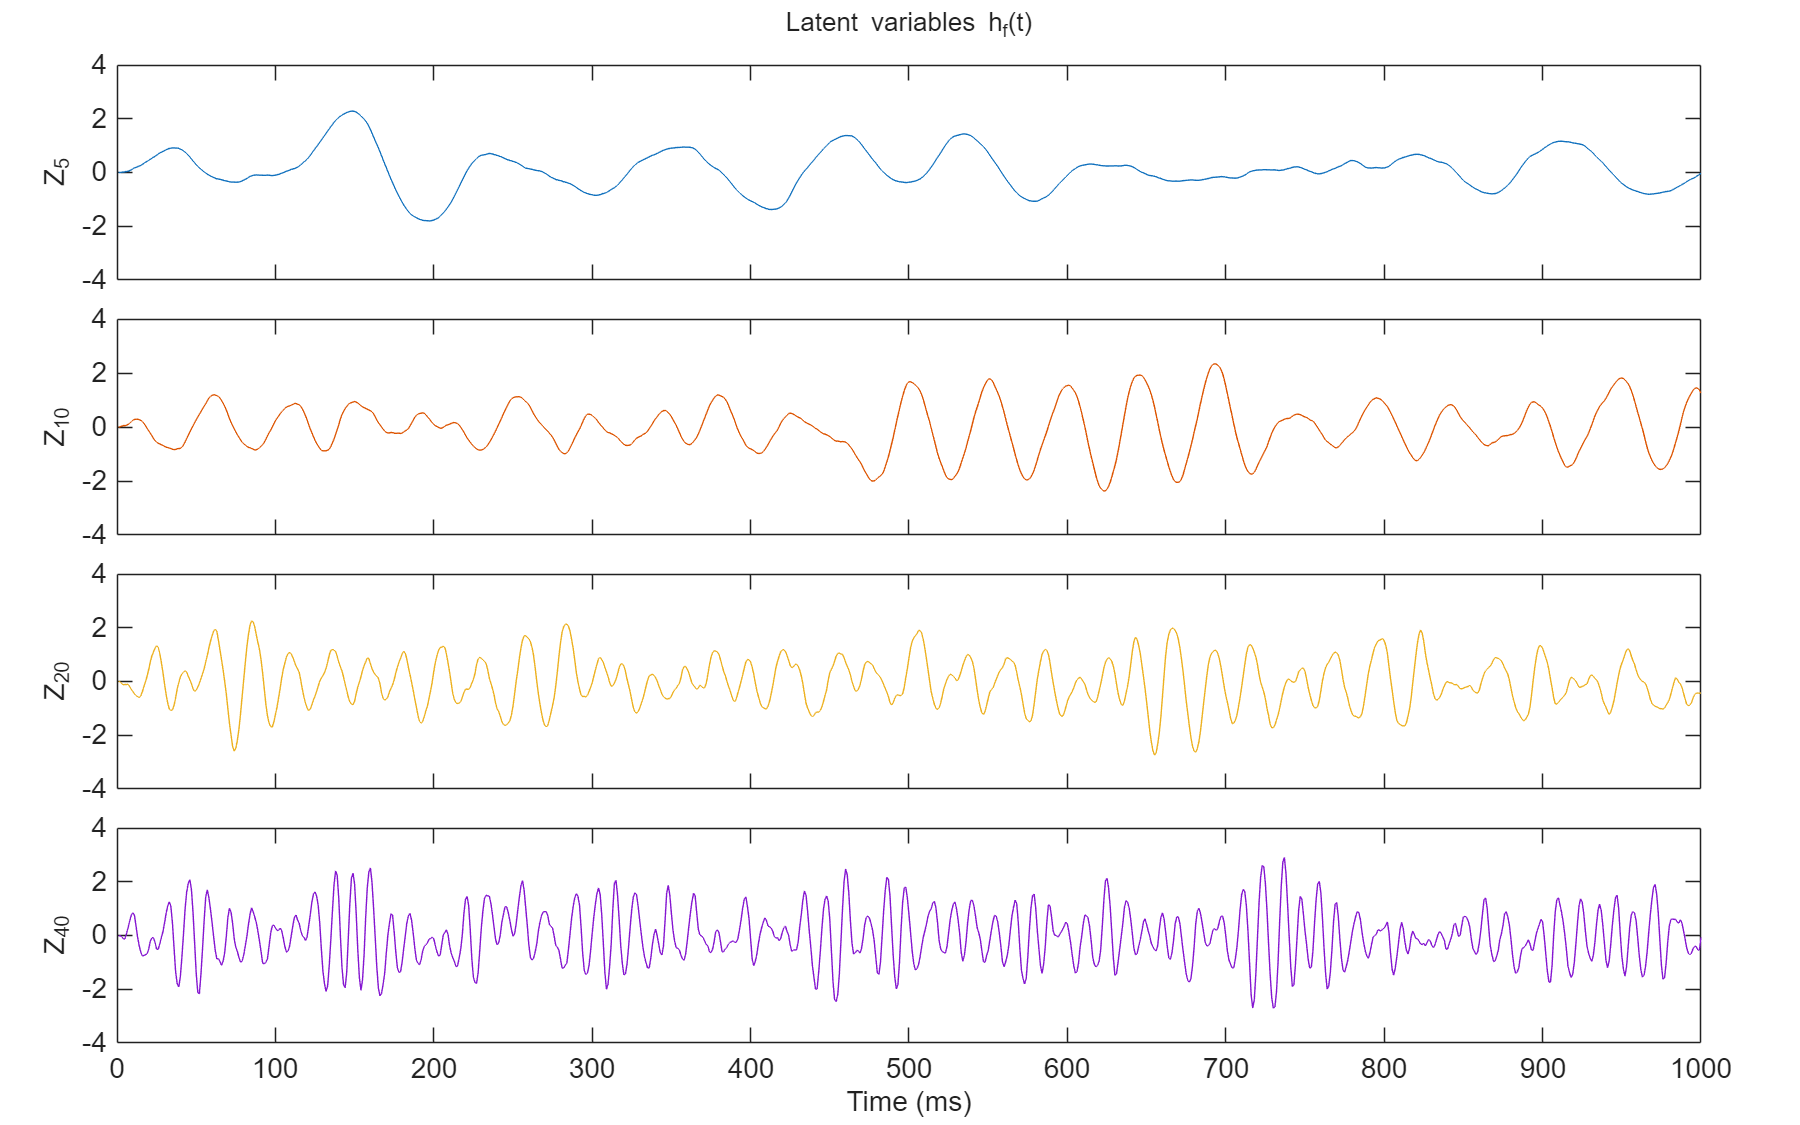


figure('Position',[50 50 1200 750])
tiledlayout(param.N_F, 1, 'TileSpacing','compact','Padding','compact');

h_f_colors = lines(param.N_F);
y_limits = [-4 4];  % force consistent y-scale

for f = 1:param.N_F
    nexttile
    plot(h_f_normalized_ds(:, f), 'Color', h_f_colors(f,:));
    xlim([0 1000]);
    ylim(y_limits);
    ylabel(sprintf('Z_{%d}', param.f_peak(f)));
    if f < param.N_F
        set(gca, 'XTickLabel', []); % hide x labels for middle plots
    else
        xlabel('Time (ms)');
    end
end

sgtitle('Latent variables h_f(t)'); % overall title
set(findall(gcf,'-property','FontSize'),'FontSize',14);

#### 1.2. Adding inhibitory neurons


% 2. Add inhibitory neurons
% ------------------------
if ~isfield(param, 'inhib_frac')
    param.inhib_frac = 0.2;  % default 20% inhibitory
end

nInhib = round(param.inhib_frac * param.N_neur);
inhib_idx = randperm(param.N_neur, nInhib);
s_i_double = double(s_i);
s_i_double_inhib = s_i_double;
s_i_double_inhib(inhib_idx, :) = -s_i_double(inhib_idx, :);  % inhibitory neurons as negative

% Display inhibitory neurons:
fprintf("Inhibitory Neuron indecies are: %s", num2str(sort(inhib_idx)));

Inhibitory Neuron indecies are: 1    7   22   27   29   33   37   43   51   55   56   70   78   89   97   98  105  111  128  133  138  139  140  141  144  150  152  159  169  171  173  177  184  192  193  195  199  208  210  214  215  218  226  230  232  239  241  243  252  254  256

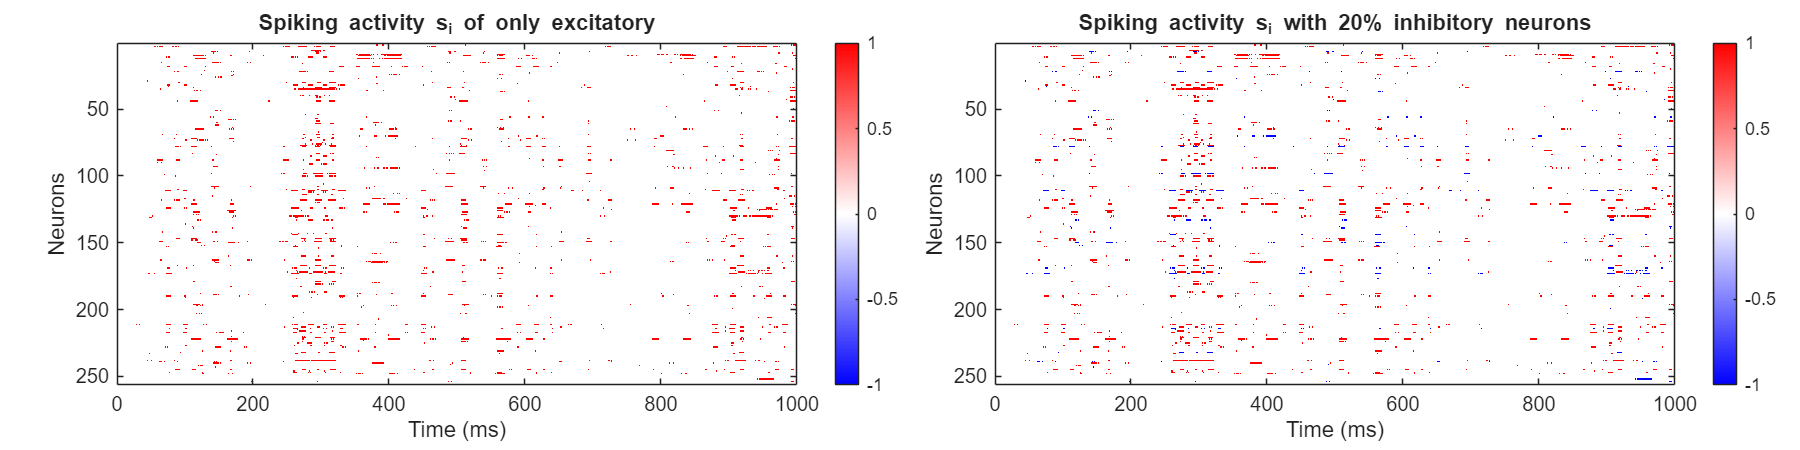

neurons_to_plot = param.N_neur; % 10 channels, 8 neuron per channel for EEG

% Custom red-white-blue colormap
n = 256;
rwb = [linspace(0,1,n/2)', linspace(0,1,n/2)', ones(n/2,1);    % blue→white
       ones(n/2,1), linspace(1,0,n/2)', linspace(1,0,n/2)'];   % white→red

half_a_sec = 0.5/param.dt;
figure('Position',[50 50 1200 300])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile
imagesc(time_ms(1:2*half_a_sec+1), 1:neurons_to_plot, s_i_double(1:neurons_to_plot, 1:2*half_a_sec+1))
xlabel('Time (ms)')
ylabel('Neurons')
xlim([0 1000]);   % show first 500 ms
title('Spiking activity s_i of only excitatory')
colormap(rwb); 
colorbar;
clim([-1 1]);

nexttile
imagesc(time_ms(1:2*half_a_sec+1), 1:neurons_to_plot, s_i_double_inhib(1:neurons_to_plot, 1:2*half_a_sec+1))
xlabel('Time (ms)')
ylabel('Neurons')
xlim([0 1000]);   % show first 500 ms
title('Spiking activity s_i with 20% inhibitory neurons')
colormap(rwb); 
colorbar;
clim([-1 1]);

#### 1.3 Convolving with post-synaptic kernel

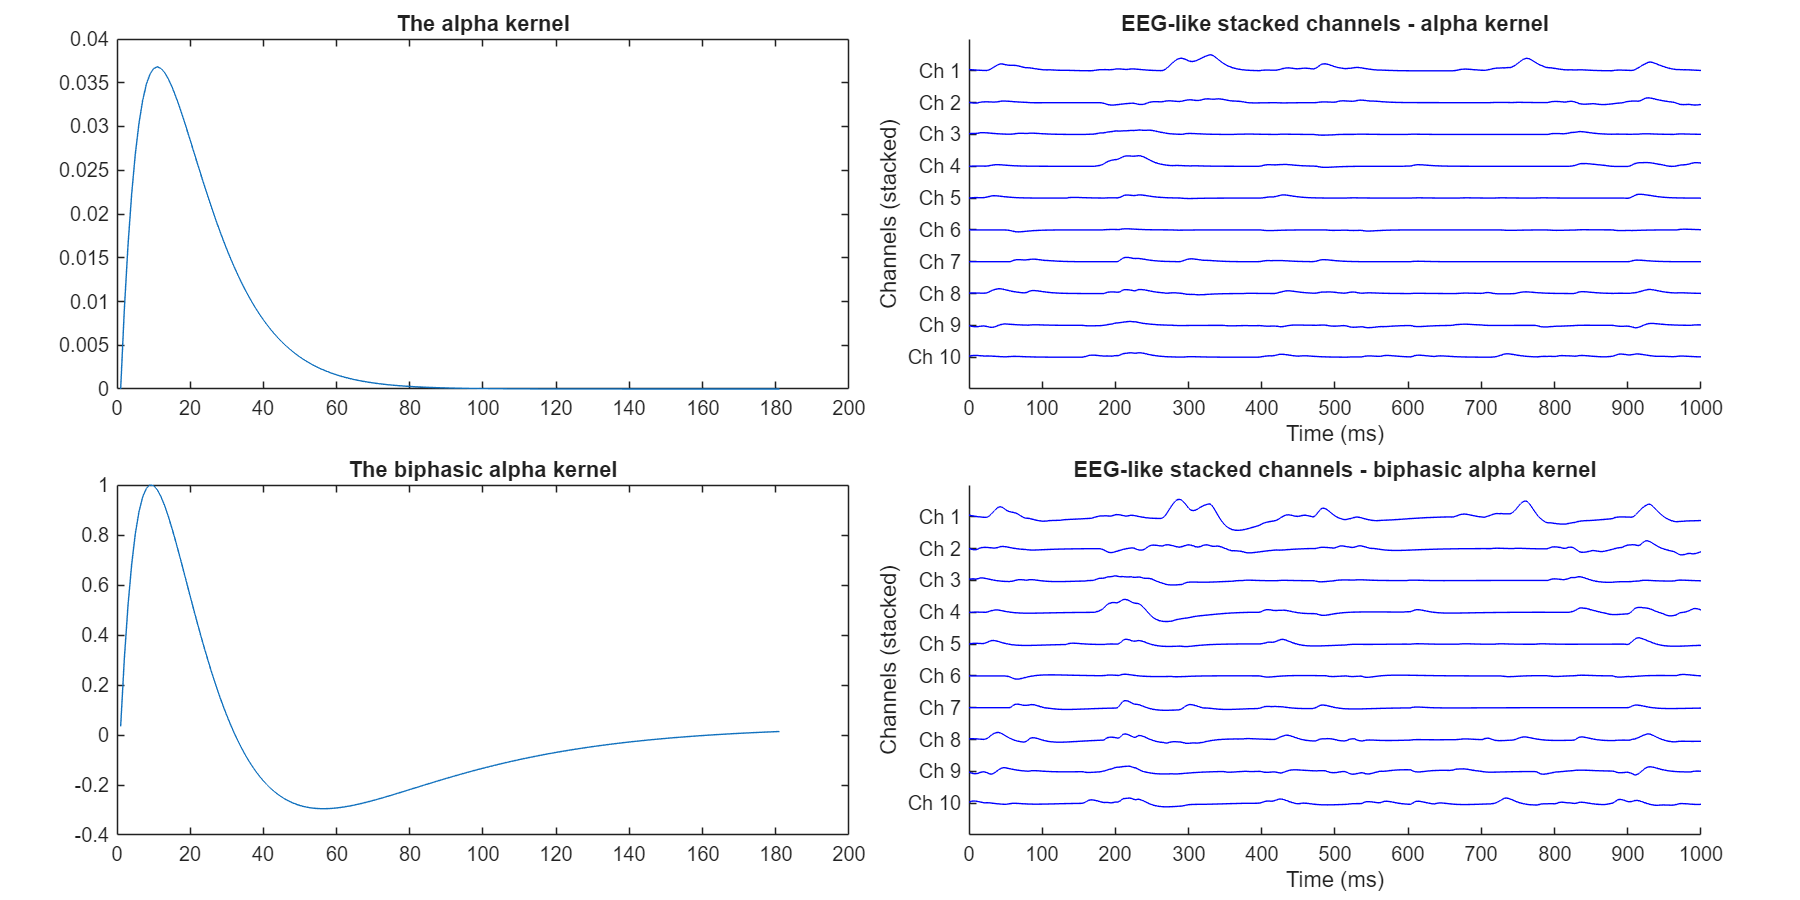


% 3. Convolving with post-synaptic kernel: choosing the Alpha kernel that
% models realistic synaptic current with rise and fall
% Alpha kernel: rise-then-decay shape
tau_pos = 0.01;       % alpha time constant for positive lobe (seconds), e.g. 10 ms
tau_neg = 0.03;       % time constant for negative lobe, e.g. 30 ms
tmax_factor = 6;      % how many taus to include (8 is safe)
dt_kernel = param.dt; % kernel sampling step (use same as sim or coarser)

% --- Build common time vector (seconds) ---
tmax = tmax_factor * max(tau_pos, tau_neg);
t = 0:dt_kernel:tmax;  % same t for all kernels

% --- Alpha kernel (canonical) ---
alpha_k = (t ./ tau_pos) .* exp(-t ./ tau_pos);
alpha_k = alpha_k / sum(alpha_k);   % normalize by area (or use max)

% Apply alpha kernel convolution per neuron
group_size = 8;
num_channels = floor(param.N_neur / group_size);
T_new = size(s_i_double_inhib,2);
s_convolved_alpha = zeros(num_channels, T_new ); % output length after conv, + length(alpha_kernel) - 1

for ch = 1:num_channels
    % Neuron indices for this group
    idx_start = (ch - 1)*group_size + 1;
    idx_end = ch * group_size;

    % Sum of convolved signals in this group
    signal = zeros(1, T_new ); %+ length(alpha_kernel) - 1
    for i = idx_start:idx_end
        spk = s_i_double_inhib(i, :);
        % Choose kernel: alpha_kernel or exp_kernel
        conv_spk = conv(spk, alpha_k, 'same');  % or 'same' to match length
        signal = signal + conv_spk;
    end

    % Store channel
    s_convolved_alpha(ch, :) = signal;
end



% --- Biphasic kernel (two-EXP difference approach, phys-like) ---
% positive lobe (fast) and negative lobe (slower, scaled)
biphasic_k = (t ./ tau_pos).*exp(-t./tau_pos) - 0.4*(t ./ tau_neg).*exp(-t./tau_neg);
% center/sink to zero mean if you want
biphasic_k = biphasic_k - mean(biphasic_k);
% normalize by peak absolute value (optional, to compare shapes)
biphasic_k = biphasic_k / max(abs(biphasic_k));


% 4. Group Neurons + Convolution
% ------------------------
num_channels = floor(param.N_neur / group_size);
num_channels_plot = 10;
s_convolved = zeros(num_channels, T_new);

for ch = 1:num_channels
    idx = (ch - 1)*group_size + (1:group_size);
    conv_sum = zeros(1, T_new);
    for i = idx
        conv_sum = conv_sum + conv(s_i_double_inhib(i, :), biphasic_k, 'same');
    end
    s_convolved(ch, :) = conv_sum;
end

figure('Position',[50 50 1200 600])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile
plot(1:length(alpha_k), alpha_k);
title("The alpha kernel");

nexttile;
offset = 5; % vertical spacing between channels
hold on

for ch = 1:num_channels_plot
    % plot each channel stacked upward
    plot(time_ms, s_convolved_alpha(ch+1,:) + (num_channels_plot - ch)*offset, 'b');
end
hold off

xlim([0 1000]);
ylim([-offset, num_channels_plot*offset]);

xlabel('Time (ms)');
ylabel('Channels (stacked)');
yticks((0:num_channels_plot-1)*offset);
yticklabels(arrayfun(@(c) sprintf('Ch %d', num_channels_plot - c + 1), 1:num_channels_plot, 'UniformOutput', false));
title('EEG-like stacked channels - alpha kernel');

nexttile
plot(1:length(biphasic_k), biphasic_k);
title("The biphasic alpha kernel");
offset = 80; % vertical spacing between channels

nexttile;
hold on

for ch = 1:num_channels_plot
    % plot each channel stacked upward
    plot(time_ms, s_convolved(ch+1,:) + (num_channels_plot - ch)*offset, 'b');
end
hold off

xlim([0 1000]);
ylim([-offset, num_channels_plot*offset]);

xlabel('Time (ms)');
ylabel('Channels (stacked)');
yticks((0:num_channels_plot-1)*offset);
yticklabels(arrayfun(@(c) sprintf('Ch %d', num_channels_plot - c + 1), 1:num_channels_plot, 'UniformOutput', false));
title('EEG-like stacked channels - biphasic alpha kernel');

#### 1.4: Centering and normalizing

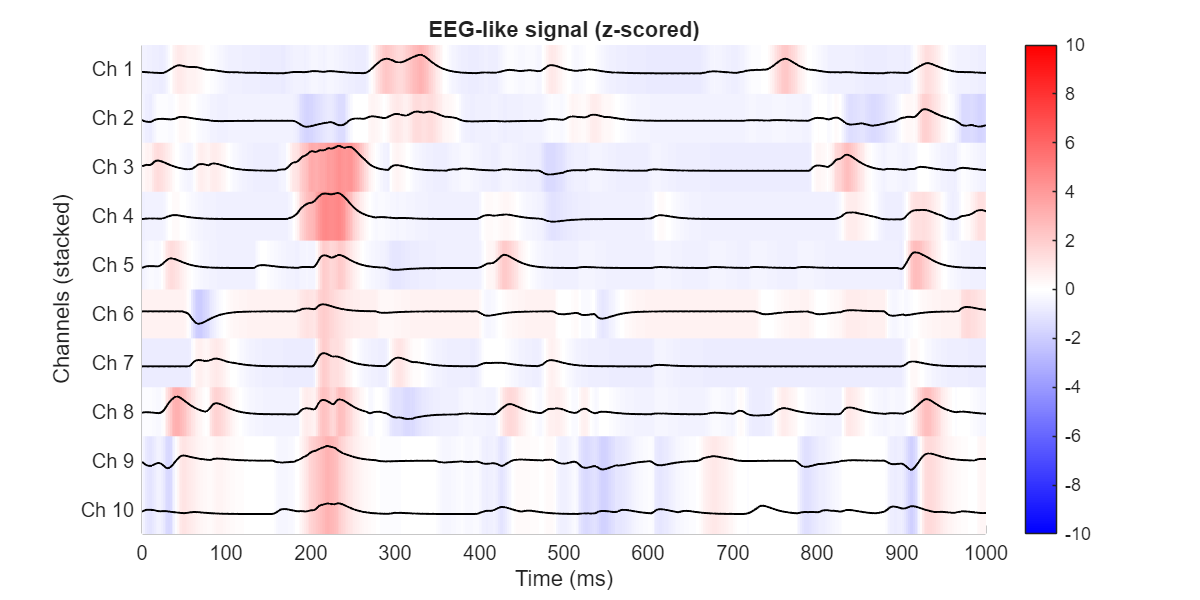


% 4. Centering and normalizing
% Z-score across time for each neuron
% Normalize (z-score) across time
s_eeg_like = zscore(s_convolved_alpha, 0, 2);

% Custom red-white-blue colormap
n = 256;
rwb = [linspace(0,1,n/2)', linspace(0,1,n/2)', ones(n/2,1);    % blue→white
       ones(n/2,1), linspace(1,0,n/2)', linspace(1,0,n/2)'];   % white→red

num_channels = 10;
offset = 10; % vertical spacing between channels

figure('Position', [50 50 800 400])
hold on;

% Plot each channel heatmap and line
for ch = 1:num_channels
    y_center = (num_channels - ch) * offset;   % same center for heatmap & trace
    
    % Corrected heatmap vertical placement
    imagesc(time_ms, ...
            [y_center - offset/2, y_center + offset/2], ...
            s_eeg_like(ch,:)); 
end

colormap(rwb);
colorbar;
clim([-10 10]);
set(gca, 'YDir', 'normal');

% Plot EEG traces on top of heatmaps
for ch = 1:num_channels
    y_center = (num_channels - ch) * offset;
    plot(time_ms, s_eeg_like(ch+1,:) + y_center, 'k', 'LineWidth', 1);
end

% Adjust limits and labels
xlim([0 1000]);
ylim([-offset/2, (num_channels-0.5)*offset]);
xlabel('Time (ms)');
ylabel('Channels (stacked)');

yticks((0:num_channels-1)*offset);
yticklabels(arrayfun(@(c) sprintf('Ch %d', num_channels - c + 1), 1:num_channels, 'UniformOutput', false));

title('EEG-like signal (z-scored)');
hold off;

## 1.5 Running the Spike to EEG function to generate synthetic EEG for training and testing


% testing Spike to EEG function:
% target_bin_size = 0.01; % 10 ms
% tau = 10; % Post-synaptic kernel, Alpha kernel's number of bins to the peak of the kernel
smooth_sigma = 2; % Std. Dev. of the Gaussian kernel in bins
group_size = 8; % grouping of neurons per channel
param.T = 120;

[s_eeg_like, h_f_processed] = spike_to_eeg(s_i, h_f, param, group_size, smooth_sigma);

[s_i_test, param_test, h_f_test] = sampleMorrellModel(param);

[MorrellModel] Using SDHO latent process.


[s_eeg_like_test, h_f_processed_test] = spike_to_eeg(s_i_test,h_f_test, param, group_size, smooth_sigma);


clear; clc;
% load test dataset
simEEG = load("simEEG_set1.mat");
s_eeg_like = simEEG.train_sim_eeg_vals;
s_eeg_like_test = simEEG.test_sim_eeg_vals;
h_f_processed = simEEG.train_true_hF';
param.f_peak = [1, 2, 3, 4, 5, 6, 7, 8];
fs_new = 1/simEEG.dt;
fs_orig= fs_new;
param.N_F = size(simEEG.train_true_hF,1);

% Marchenko–Pastur threshold
eig_vals = eig(cov(s_eeg_like'));
[N, T] = size(s_eeg_like);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
% num_sig_components = param.N_F; 
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 2 PCs


## 1.5.1 Downsampling and PSD plots using DFT and Welch's methods


% ---- parameters ----

decimate_factor = fs_orig / fs_new;  % should be integer (16)

% --- 0) ensure h_f is double and shaped [T x N_F] ---
h_f_processed = double(h_f_processed);

% --- 1) Resample latent fields to fs_new (vectorized via loop over columns) ---
[T_orig, N_F] = size(h_f_processed);
T_est = ceil(T_orig * fs_new / fs_orig);
h_f_processed_ds = zeros(T_est, N_F);
for ff = 1:N_F
    h_f_processed_ds(:, ff) = resample(h_f_processed(:, ff), fs_new, fs_orig);   % returns column vector
end
T_ds = size(h_f_processed_ds,1);
%% TODO: remove the DFT 
% ---- 2) DFT Periodogram on downsampled signals (fast, single FFT per column) ----
% choose nfft reasonable (power of 2)
nfft_dft = 2^nextpow2(T_ds);
H = fft(h_f_processed_ds, nfft_dft);              % nfft x N_F
% keep only one-sided spectrum
half = floor(nfft_dft/2)+1;
freq_dft = (0:half-1)*(fs_new/nfft_dft);
H_F_dft_psd = (1/(fs_new * nfft_dft)) * abs(H(1:half,:)).^2;  % PSD: freq x N_F

% ---- 3) Welch PSD on downsampled signals (recommended) ----
% choose window and nfft relative to fs_new (e.g. 1024 samples => ~2.048 s at 500 Hz)
win_len = 2000;                    % window length in samples (tunable)
if win_len > T_ds
    win_len = 2^floor(log2(T_ds/4));   % fallback to smaller window
end
noverlap = round(win_len/2);       % 50% overlap
nfft_welch = 4000;                 % frequency resolution, tunable (>= win_len)

window = hamming(win_len);
% pwelch accepts matrix input with columns = channels (time x channels)
[H_F_welch_psd, f_welch_psd] = pwelch(h_f_processed_ds, window, noverlap, nfft_welch, fs_new);
% H_F_welch_psd is nFreq x N_F

% ---- 4) Optional: quick checks / plotting ----
fprintf('Original T = %d samples -> downsampled T_ds = %d samples (fs=%d Hz)\n', T_orig, T_ds, fs_new);

Original T = 120000 samples -> downsampled T_ds = 120000 samples (fs=200 Hz)


fprintf('Welch: window=%d, overlap=%d, nfft=%d, nFreq=%d\n', win_len, noverlap, nfft_welch, size(H_F_welch_psd,1));

Welch: window=2000, overlap=1000, nfft=4000, nFreq=2001


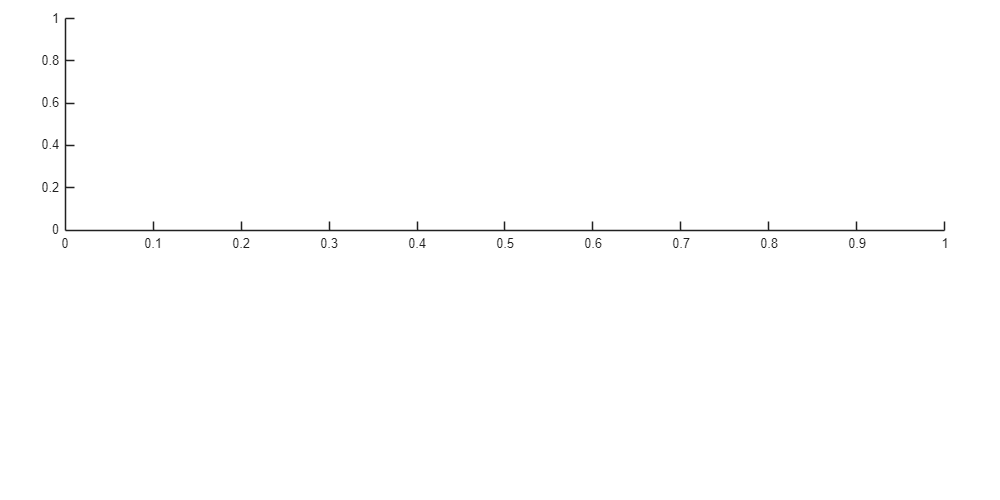

figure('Position',[50 50 1000 500])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);

nexttile
hold on;

num_latent = param.N_F;
offset_lat = 6 * std(h_f_processed(:,1));  % vertical spacing
 t_plot = (0:(1/fs):2)';

Unrecognized function or variable 'fs'.

for f=1:num_latent
    plot(t_plot,h_f_processed(1:length(t_plot), f)+ (num_latent - f)*offset_lat, 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
end

hold off;
xlim([0 2]);
ylim([-offset_lat, num_latent*offset_lat]);
xlabel('Time (s)');
ylabel('Latents (stacked)');
yticks((0:num_latent-1)*offset_lat);
yticklabels(arrayfun(@(c) sprintf('z_%d', num_latent - c + 1), 1:num_latent, 'UniformOutput', false));
title('Latent Variables (stacked)');

% nexttile
% for f=1:param.N_F
%     loglog(freq_dft, H_F_dft_psd(:,f),'Color',h_f_colors(f,:),'DisplayName',['DFT(Z_{' num2str(f) '} (t))']);
%     hold on;
% end
% xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
% ylim([1e-7, 1]);
% yticks([0.00001, 0.0001, 0.001, 0.01, 1]);
% xlabel('Freq. (Hz)'); ylabel('PSD (units^2/Hz)');
% title('DFT Periodogram estimate');
% legend('show', 'Location','southeastoutside');
% xlim([1, 50]);
% hold off;

nexttile
for f=1:param.N_F
    loglog(f_welch_psd, H_F_welch_psd(:,f),'Color',h_f_colors(f,:),'DisplayName',['Welch(Z_{' num2str(f) '} (t))']); % 
    hold on;
end
xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
yticks([0.003, 0.005, 0.01, 0.02]);
%  ylim([0.00001, 1]);
yticks([0.00001, 0.0001, 0.001, 0.01, 1]);
xlabel('Frequency bins')
ylabel('Power/Freq (dB/Hz)')
title('Welch Periodogram')
legend('show', 'Location','southeastoutside');
xlim([1, 50]);
hold off;
set(findall(gcf,'-property','FontSize'),'FontSize',16);

## II. Custom Autoencoder

[nCh, T_orig] = size(s_eeg_like);

% Preallocate downsampled matrix: estimate new length
T_new_est = ceil(T_orig * fs_new / fs_orig);
s_eeg_ds = zeros(nCh, T_new_est);
s_eeg_test_ds = zeros(nCh, T_new_est);

for ch = 1:nCh
    % resample expects vector input, returns column vector
    y = resample(double(s_eeg_like(ch, :))', fs_new, fs_orig);  % Tnew x 1
    s_eeg_ds(ch, 1:length(y)) = y';

    y_test = resample(double(s_eeg_like_test(ch, :))', fs_new, fs_orig);  % Tnew x 1
    s_eeg_test_ds(ch, 1:length(y_test)) = y_test';
end
% trim to actual length
T_ds = size(y,1);
s_eeg_ds = s_eeg_ds(:, 1:T_ds);
s_eeg_test_ds = s_eeg_test_ds(:, 1:T_ds);

% Use only 10-20% of your data for training
subset_size = round(0.1 * size(s_eeg_ds , 2));
s_eeg_ds_small = s_eeg_ds(:, 1:subset_size);

% --- 2) Resample latent fields (time x N_F) ---
% TODO: also downsample the test h_f
h_f_ds = [];
h_f_test_ds = [];

for fidx = 1:N_F
    h_f_ds(:, fidx) = resample(double(h_f_processed(:, fidx)), fs_new, fs_orig);
    % h_f_test_ds(:, fidx) = resample(double(h_f_processed_test(:, fidx)), fs_new, fs_orig);
end


% Normalize latent variables by their variance (per column)
h_f_normalized_ds = h_f_ds ./ std(h_f_ds, 0, 1);  % Time × N_F
% h_f_normalized_test_ds = h_f_test_ds ./ std(h_f_test_ds, 0, 1); 

h_f_normalized = h_f_processed ./ std(h_f_processed, 0, 1);
% h_f_normalized_test = h_f_processed_test ./ std(h_f_processed_test, 0, 1);

## 2.1 Parameter setup

X = s_eeg_like;

batch_size = 80; % fs_new
% batch_size = 256;
bottleNeck = 10; % 8
T = size(X,2);

idx_split = floor(0.8*T);
X_train = X(:,1:idx_split);
X_test  = X(:,idx_split+1:end);

H_train = h_f_normalized(1:idx_split, :);
H_test  = h_f_normalized(idx_split+1:end, :);

% winLen = 40*32;       % round(1 * fs), 1 second windows
% hop = round(winLen/2);        % 50% overlap
% Xtr_w = make_windows(X_train, winLen, hop);   % rows = windows
% Xte_w = make_windows(X_test,  winLen, hop);
% Now train with inputDim = nCh*winLen (modify network input accordingly)
% Z to h_f: use some linear matrix transformation to see if we can figure out which is which latent
% 


## 2.2 Running the Autoencoder model

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.66 |         0.63 |       0.2194 |       0.2003 |          0.0010 |
|       1 |          50 |       00:00:04 |         0.21 |              |       0.0221 |              |          0.0010 |
|       1 |         100 |       00:00:04 |         0.12 |              |       0.0068 |              |          0.0010 |
|       1 |         150 |       00:00:05 |         0.10 |              |       0.0048 |              |          0.0010 |
|       

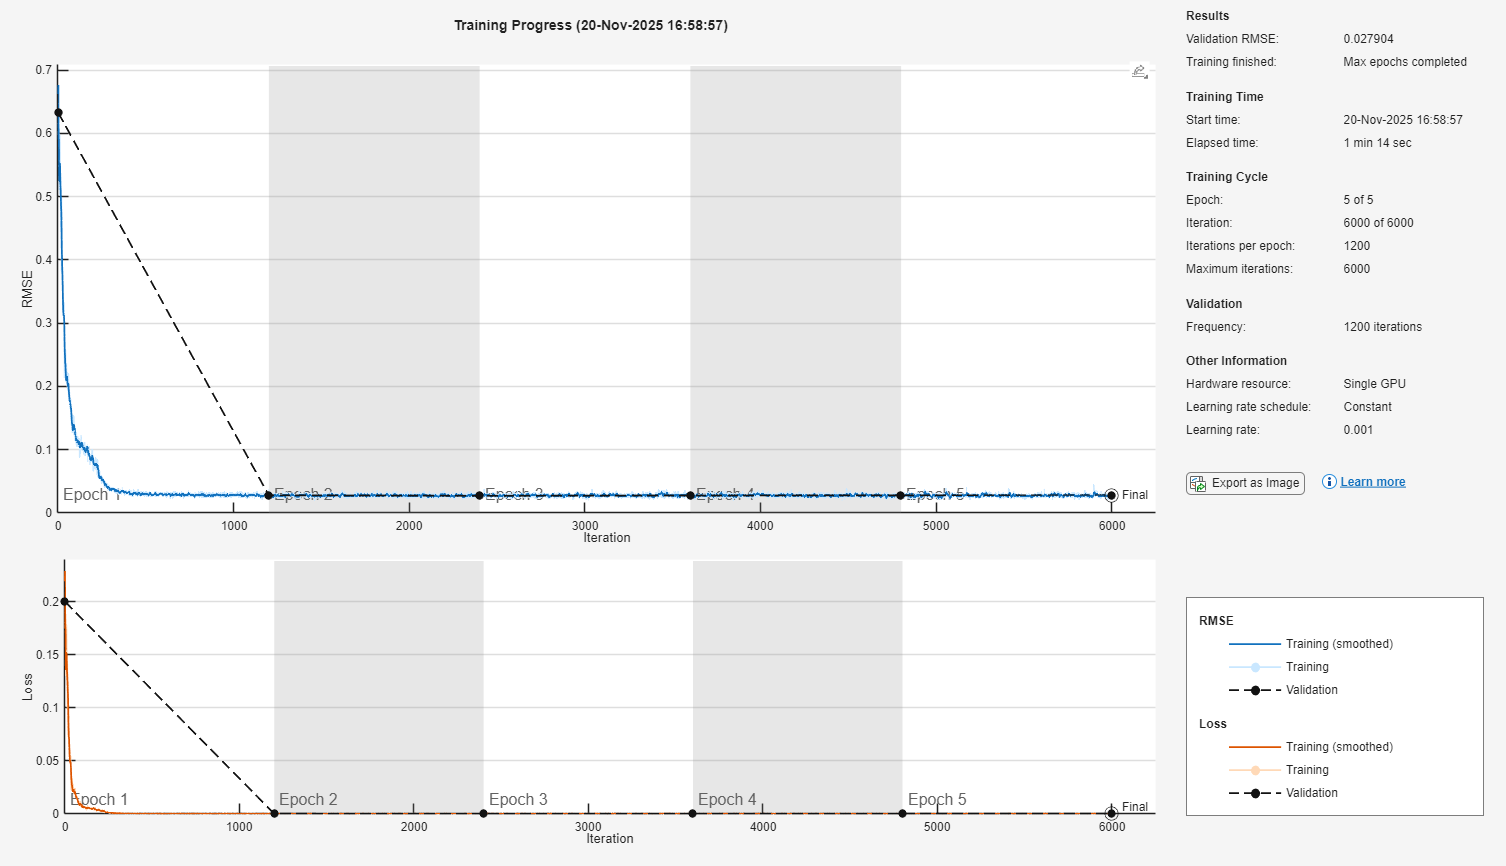

[net, info] = trainEEGAutoencoder(X_train, X_test,  ...
    'encoderLayerSizes', [64,32], ...
    'bottleneckSize', bottleNeck, ...
    'decoderLayerSizes', [32,64], ...
    'encoderActivations', {'relu','relu'}, ...
    'decoderActivations', {'relu','relu'}, ...
    'outputActivation', "none", ...
    'epochs', 5, ...
    'batchSize', batch_size, ...
    'learnRate', 1e-3);

net

net =   SeriesNetwork with properties:

         Layers: [12×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'mse'}

## 2.3 Encode into latent space and getting the bottle neck variables

Z_train_c = activations(net, X_train.', 'bottleneck', 'OutputAs','rows');
Z_test_c  = activations(net, X_test.',  'bottleneck', 'OutputAs','rows');


## 2.4 Figuring out which Z_trian_c variable corresponds to which h_f latent

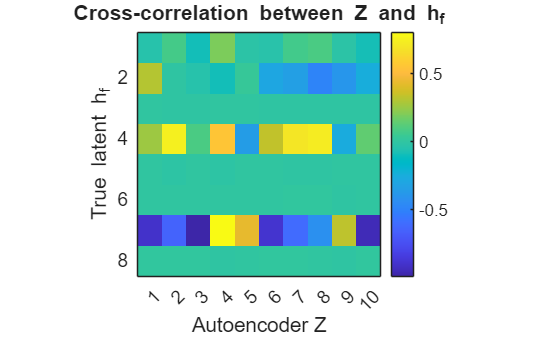

% variable:
Z = zscore(Z_train_c);
H = zscore(h_f_normalized(1:idx_split, :));
R = corr(H, Z);   % size: [num_Z × num_H]
figure();
imagesc(R); colorbar; ylabel('True latent h_f'); xlabel('Autoencoder Z');
title('Cross-correlation between Z and h_f');
xticks(1:bottleNeck);
yticks('auto');

% Optionally, make it prettier
axis square;
set(gca, 'TickLength', [0 0]); % remove tick marks
set(gca, 'FontSize', 14);

[best_corr, match_idx] = max(abs(R), [], 2);

corr_table = table((1:size(H,2))', match_idx, best_corr, 'VariableNames', {'h_f', 'Z_match_idx', 'corr_value'})

corr_table = 8×3 table
    h_f    Z_match_idx    corr_value
    ___    ___________    __________
     1          4           0.19917 
     2          8           0.48869 
     3          8         0.0053034 
     4          2           0.75063 
     5          4          0.010578 
     6          8         0.0056369 
     7          3            0.9888 
     8          1         0.0085689 

% % Reorder by h_f index (to print in h_f → Z order)
% [h_f_sorted, sort_idx] = sort(corr_table.Z_match_idx);
% Z_sorted   = corr_table.h_f(sort_idx);
% corr_sorted = corr_table.corr_value(sort_idx);
% 
% % Build clean table
% match_table = table(h_f_sorted, Z_sorted, corr_sorted, ...
%     'VariableNames', {'Z', 'h_F', 'Corr_value'});
% 
% disp('Matched latent indices (h_f → Z):');
% disp(match_table);

- Looks like Z4 to 1 cross correlation decrease with h_f variables, and somewhat match except for Z3 that match with h_f 1. 

## 2.4.1 Canonical Correlation Analysis (CCA):

[A,B,r,U,V] = canoncorr(Z, H);

k = numel(r);
p = size(Z,2);
q = size(H,2);

% 1) print canonical correlations
fprintf('Canonical correlations (k=%d):\n', k);

Canonical correlations (k=4):


disp(r(:)');

    0.9999    0.9998    0.9993    0.0041


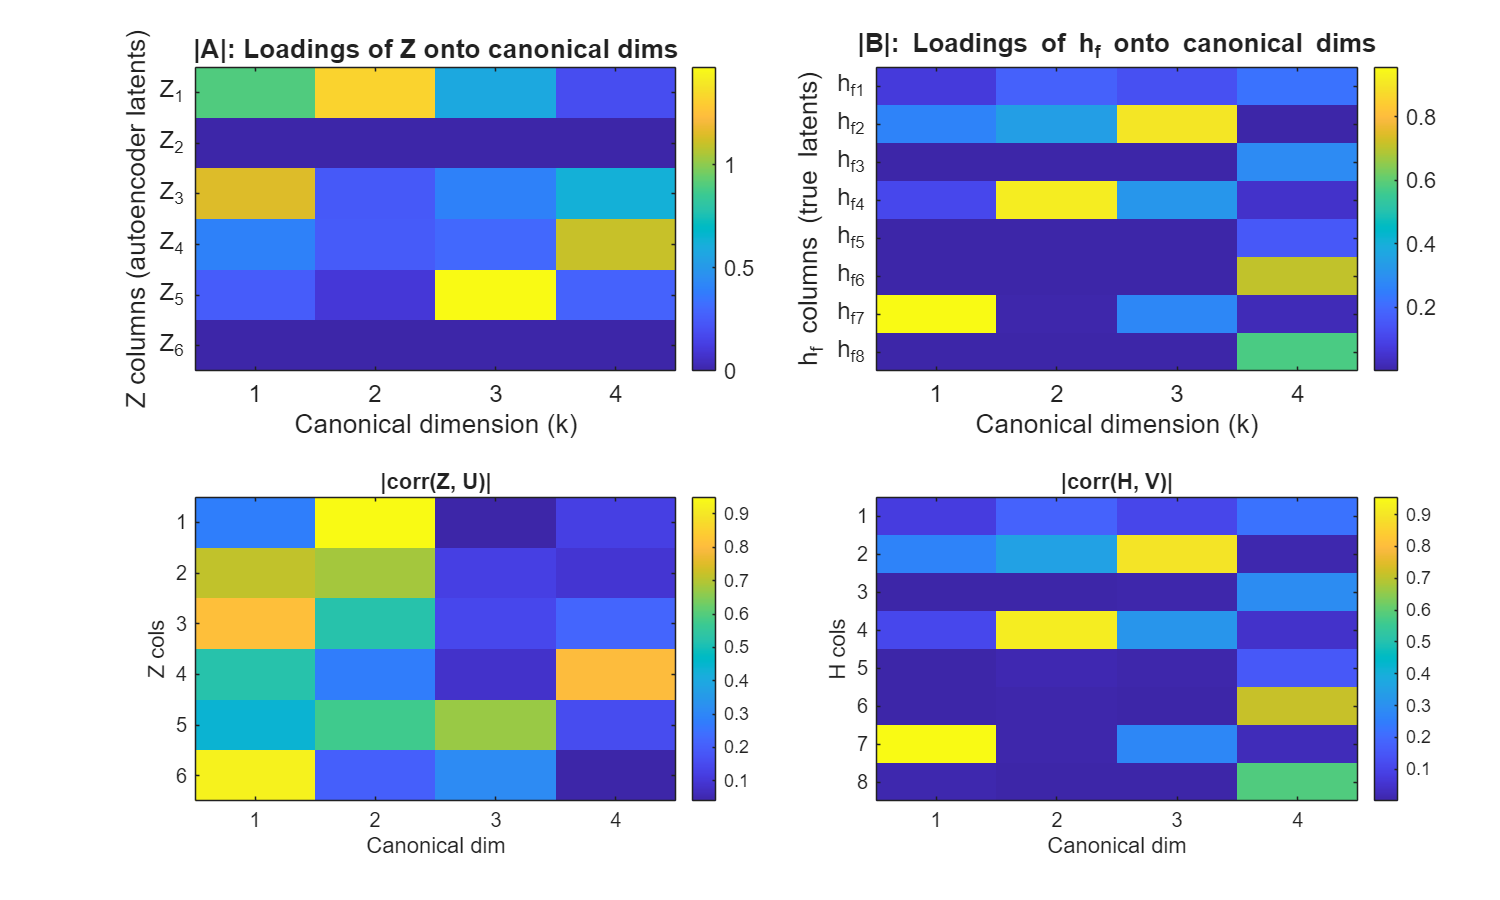


% 2) Heatmap of absolute coefficients A (rows: Z cols, cols: canonical dims)
figure('Position',[50 50 1000 600])
tiledlayout(2, 2); %, 'TileSpacing', 'compact', 'Padding', 'compact'
nexttile;
imagesc(abs(A));
colormap(parula); colorbar;
xlabel('Canonical dimension (k)');
ylabel('Z columns (autoencoder latents)');
title('|A|: Loadings of Z onto canonical dims');
xticks(1:k);
yticks(1:p);
yticklabels(arrayfun(@(i) sprintf('Z_{%d}', i ), 1:p, 'UniformOutput', false));
set(gca,'FontSize',12,'XTickLabelRotation',0);

% 3) Heatmap of absolute coefficients B (rows: H cols, cols: canonical dims)
nexttile;
imagesc(abs(B));
colormap(parula); colorbar;
xlabel('Canonical dimension (k)');
ylabel('h_f columns (true latents)');
title('|B|: Loadings of h_f onto canonical dims');
xticks(1:k);
yticks(1:q);
yticklabels(arrayfun(@(i) sprintf('h_f_%d', i), 1:q, 'UniformOutput', false));
set(gca,'FontSize',12);

% 4) Cross-loadings (optional but very useful)
% correlation between original vars and canonical variates:
CorrZ_U = corr(Z, U);   % p x k
CorrH_V = corr(H, V);   % q x k

nexttile;
imagesc(abs(CorrZ_U)); colorbar;
title('|corr(Z, U)|'); xlabel('Canonical dim'); ylabel('Z cols');
xticks(1:k); yticks(1:p);

nexttile;
imagesc(abs(CorrH_V)); colorbar;
title('|corr(H, V)|'); xlabel('Canonical dim'); ylabel('H cols');
xticks(1:k); yticks(1:q);

- H_f 1 have high corr with c_d 2 and c_d 2 with Z_6.

- H_f 2 have high corr with c_d 3 and c_d 3 with Z_5.

- H_f 4 have high corr with c_d 4 and c_d 4 with Z_1.

- H_f 3 have medium corr with c_d 3 and c_d 1, and c_d 3 with Z_4 and Z_5. Likely match is h_f 3 with Z_4.

- **This results match Correlation results.**

## 2.4.2 Singular Value Decomposition.

% There is mixing of Z happening to map to h_f variables, although Z2 and
% h_f 2 have high cannonical correlations. Let's try SVD: H ~= Z*M
figure()
M = (Z' * Z) \ (Z' * H);  % H to Z mapping

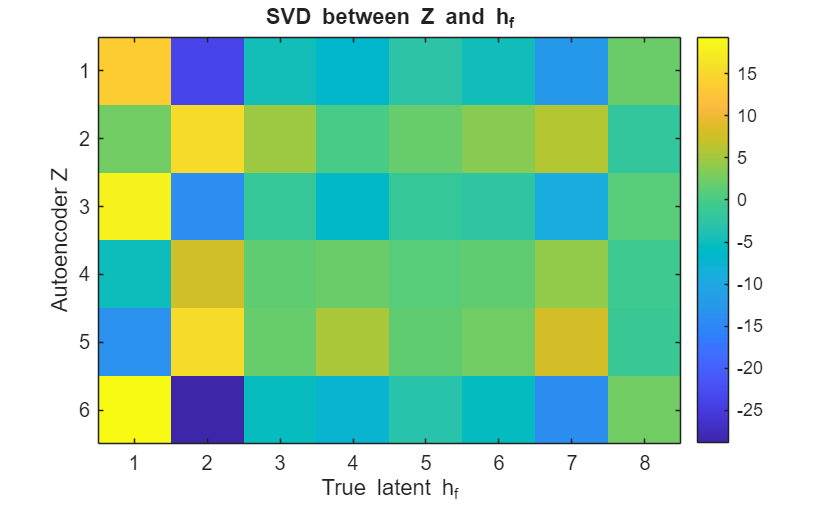


imagesc(M); colorbar; xlabel('True latent h_f'); ylabel('Autoencoder Z');
title('SVD between Z and h_f');
xticks(1:param.N_F);
yticks(1:bottleNeck);

## 2.4.3 2-layer Neural Net

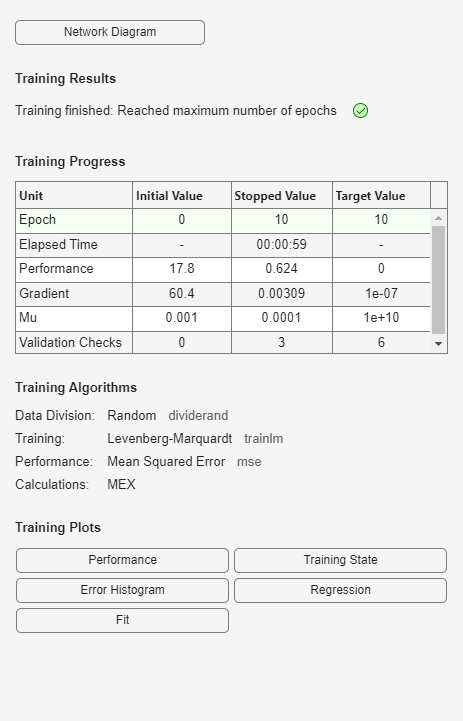

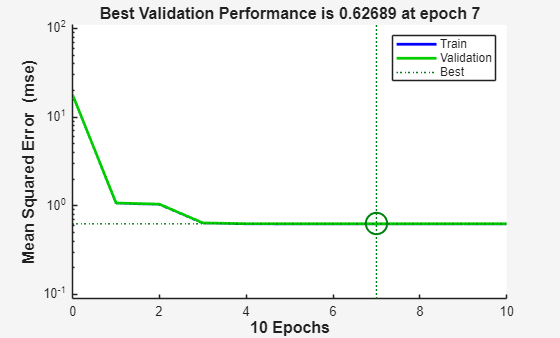

% ensuring the sizes of Z and h_f match:
minLen = min(size(Z_train_c,1), size(H_train,1));
Z_train_c = Z_train_c(1:minLen,:);
H_train = H_train(1:minLen,:);

% Define network with two hidden layers
hiddenSizes = [20 10]; % e.g., first layer: 20 neurons, second: 10 neurons
hz_net = fitnet(hiddenSizes, 'trainlm');   % Levenberg–Marquardt optimizer

% Training options
hz_net.trainParam.showWindow = true;
hz_net.trainParam.epochs = 10;
hz_net.divideParam.trainRatio = 0.8;
hz_net.divideParam.valRatio   = 0.2;
hz_net.divideParam.testRatio  = 0.0;

% Train on Z→H mapping
[hz_net, tr] = train(hz_net, Z_train_c.', H_train.');

## 2.4.3.1 Plotting the result of NN mapping

pred_H_train = hz_net(Z_train_c.').';
pred_H_test  = hz_net(Z_test_c.').';

corr_vals = zeros(1, size(H_train,2));
for i = 1:size(H_train,2)
    corr_vals(i) = corr(H_train(:,i), pred_H_train(:,i));
end
disp('Correlation between true h_f and predicted h_f from Z:');

Correlation between true h_f and predicted h_f from Z:


disp(corr_vals);

    0.2251    0.9992    0.0144    0.9796    0.0172    0.0081    0.9942    0.0140


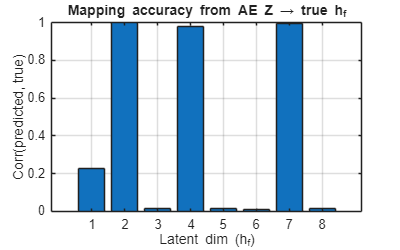


figure('Position',[50 50 400 250]);
bar(corr_vals);
xlabel('Latent dim (h_f)');
ylabel('Corr(predicted, true)');
title('Mapping accuracy from AE Z → true h_f');
grid on;

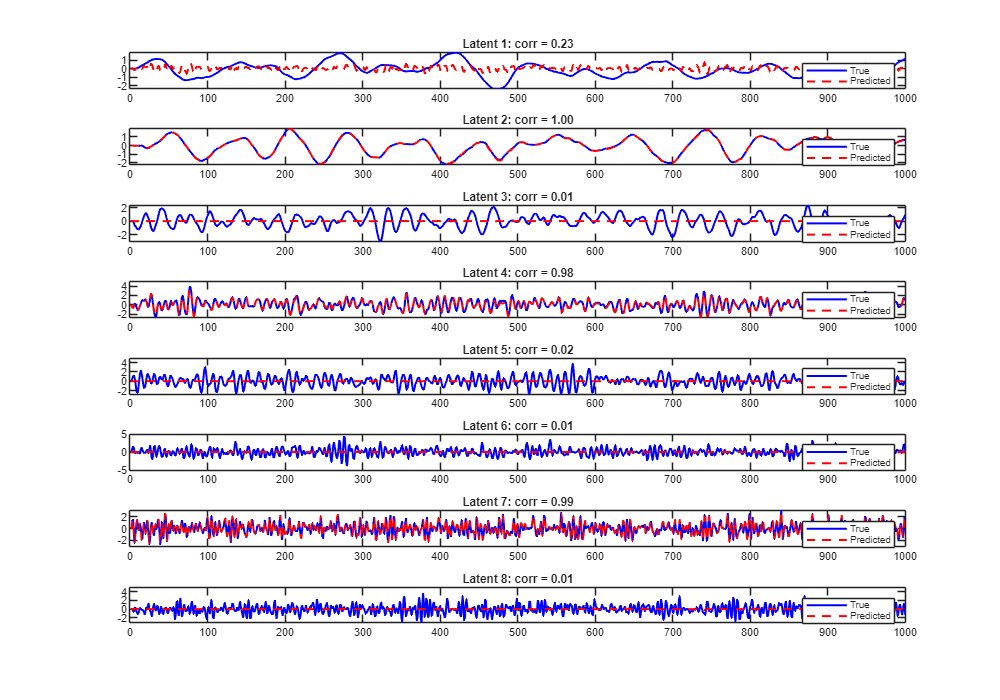


figure('Position',[50 50 1000 700])
tiledlayout(param.N_F, 1); %, 'TileSpacing', 'compact', 'Padding', 'compact'
for i = 1:min(param.N_F, size(H_train,2))
    nexttile;
    plot(H_train(1:1000,i), 'b', 'LineWidth', 1.5); hold on;
    plot(pred_H_train(1:1000,i), 'r--', 'LineWidth', 1.5);
    legend('True', 'Predicted');
    title(sprintf('Latent %d: corr = %.2f', i, corr_vals(i)));
end

% % Reconstruct from autoencoder directly
% Xrec_train = predict(net, X_train.');
% Xrec_test  = predict(net, X_test.');
% 
% % Reshape reconstructed windows back to [channels × time]
% nCh = size(X_train, 1);
% Xrec_train_full = overlap_add(Xrec_train, h_f_normalized(1:idx_split,:), winLen);
% Xrec_test_full  = overlap_add(Xrec_test,  h_f_normalized(idx_split+1:end, :), winLen);

## 2.4.3.2 Plot the train and test

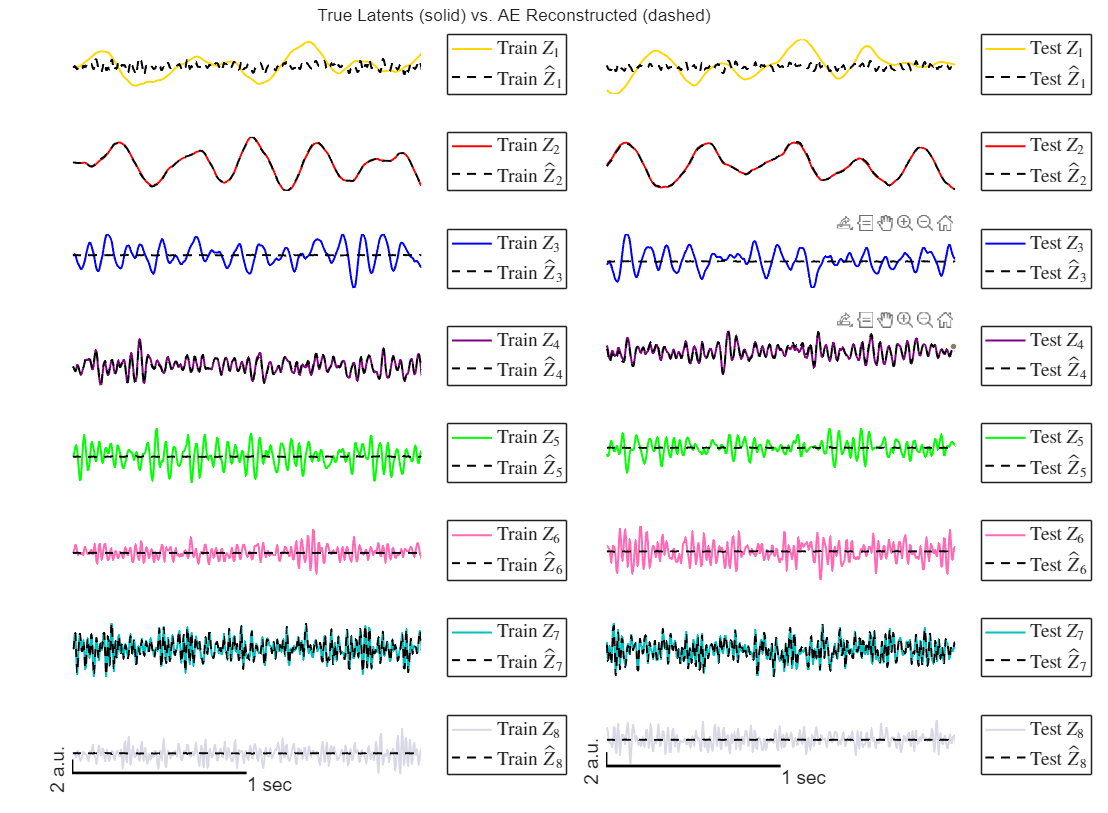

% Define the colors: yellow, red, blue, purple
cols = [
    1.0, 0.8431, 0.0;   % gold
    1.0, 0.0, 0.0;   % red
    0.0, 0.0, 1.0;   % blue
    0.5, 0.0, 0.5;   % purple
    0.0, 1.0, 0.0    % Green
    1.0, 0.41,   0.71;  % hot pink
    0.0, 0.75,   0.75;  % teal/cyan
    0.85, 0.85,    0.9   % lavender-ish light tone
];

% Extract matched Z indices in order of h_f
% matched_Z_idx = corr_table.Z_match_idx;

% Prepare figure
figure('Name','True vs. AE Latents (Overlayed Subplots)', 'Position', [100, 100, 1200, 110*param.N_F]);
tiledlayout(param.N_F, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('True Latents (solid) vs. AE Reconstructed (dashed)');

for f = 1:param.N_F
    % z_idx = matched_Z_idx(f);  % get the Z column corresponding to this h_f
    t_l = length(H_test(:,1));

    nexttile;
    hold on;
    set(gca, 'XColor', 'none', 'YColor', 'none');
    box on
    plot(1:idx_split, H_train(:,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5,'DisplayName', ['Train $Z_{' num2str(param.f_peak(f)) '}$']); 
    plot(1:idx_split, pred_H_train(:,f), '--', 'Color', 'k', 'LineWidth', 1.5,'DisplayName', ['Train $\hat{Z}_' num2str(param.f_peak(f)) '$']);
    % ylabel(sprintf('h_f {%s}Hz', num2str(param.f_peak(f))));
    % xlabel('Time bin');
    xlim([0 fs_new*2]);
    legend('location', 'southeastoutside', 'Interpreter', 'latex');
    % grid on;
    % hold off;
    if f == param.N_F
        %set(gca, 'XTickLabel', []);
        x0 = 0;           % starting point of scale bar (x)
        y0 = min(ylim)+0.2; % bottom of scale bar (y)
        
        % time bar (horizontal)
        line([x0 x0+(fs_new)], [y0 y0], 'Color', 'k', 'LineWidth', 2,'HandleVisibility', 'off');
        text(x0+fs_new, y0-0.1, '1 sec', 'VerticalAlignment','top');
        
        % amplitude bar (vertical)
        line([x0 x0], [y0 y0+2], 'Color', 'k', 'LineWidth', 2,'HandleVisibility', 'off');
        text(x0-5, y0+4, '2 a.u.', 'VerticalAlignment','bottom','HorizontalAlignment','right','Rotation',90);
        hold off;
    end

    nexttile;
    hold on;
    set(gca, 'XColor', 'none', 'YColor', 'none');
    box on
    plot(1:t_l, H_test(:,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5, 'DisplayName',['Test $Z_{' num2str(param.f_peak(f)) '}$']);  
    plot(1:t_l, pred_H_test(:,f),      '--', 'Color', 'k', 'LineWidth', 1.5, 'DisplayName', ['Test $\hat{Z}_' num2str(param.f_peak(f)) '$']);
    % ylabel(sprintf('h_f {%s}Hz', num2str(param.f_peak(f))));
    % xlabel('Time bin');
    xlim([0 fs_new*2]);
    legend('location', 'southeastoutside','Interpreter','latex');
    % grid on;
    % hold off;
    if f == param.N_F
        %set(gca, 'XTickLabel', []);
        x0 = 0;           % starting point of scale bar (x)
        y0 = min(ylim)+0.2; % bottom of scale bar (y)
        
        % time bar (horizontal)
        line([x0 x0+(fs_new)], [y0 y0], 'Color', 'k', 'LineWidth', 2,'HandleVisibility', 'off');
        text(x0+fs_new, y0-0.1, '1 sec', 'VerticalAlignment','top');
        
        % amplitude bar (vertical)
        line([x0 x0], [y0 y0+2], 'Color', 'k', 'LineWidth', 2,'HandleVisibility', 'off');
        text(x0-5, y0+4, '2 a.u.', 'VerticalAlignment','bottom','HorizontalAlignment','right','Rotation',90);
        hold off;
     end

end

set(findall(gcf,'-property','FontSize'),'FontSize',14);

## 2.4.3.3 PSD, band-wise spectra R^2 and coherence

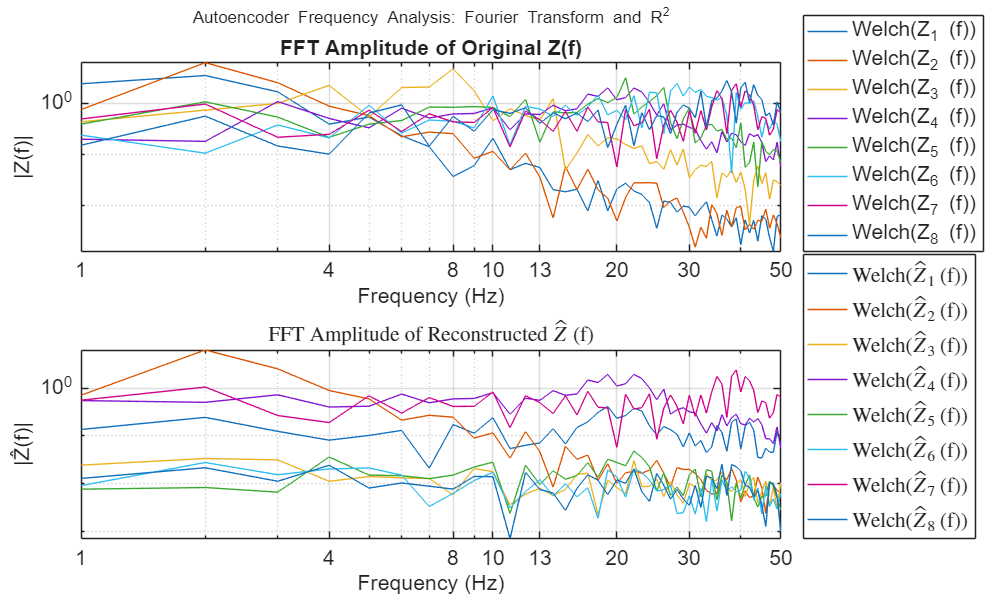

N = size(pred_H_train, 1);
trial_dur = 1;                 % seconds per "trial"
L         = trial_dur * fs_orig;    % samples per trial
nTrials   = floor(N/L);

fs = fs_orig;  % or whatever your sample rate is
f = (0:L-1)*(fs_orig/L);    % frequency vector for each trial

% Compute R^2(f)
R2_trials_ae = zeros(L, param.N_F, nTrials);
Ht_ae = zeros(L, param.N_F, nTrials);
Hr_ae = zeros(L, param.N_F, nTrials);
Z_true_trials   = zeros(L, nTrials, param.N_F);
Z_recon_ae_trials  = zeros(L, nTrials, param.N_F);


for tr = 1:nTrials
    idx = (tr-1)*L + (1:L);        % sample indices for this trial
  
    % extract one trial
    Z_true_trials(:,tr,:)  = H_train(idx,:);      
    Z_recon_ae_trials(:,tr,:) = pred_H_train(idx,:);
    
    % FFT each latent dim
    Ht_ae(:,:,tr) = fft(Z_true_trials(:,tr,:));     % size [L×N_F]
    Hr_ae(:,:,tr) = fft(Z_recon_ae_trials(:,tr,:));
    
    % compute trial‐wise R^2(f) for each dimension
    for fidx = 1:param.N_F
        num = abs(Ht_ae(:,fidx,tr) - Hr_ae(:,fidx,tr)).^2;
        den = abs(Ht_ae(:,fidx,tr)).^2 + eps;   % avoid zero‐divide
        R2_trials_ae(:,fidx,tr) = 1 - num./den;
    end
end

% Now average across trials
R2_avg_ae = mean(R2_trials_ae, 3);   % [L×N_F]
Ht_avg_ae = mean(Ht_ae, 3);
Hr_avg_ae = mean(Hr_ae, 3);

nHz = L/2+1;
f_plot = f(1:nHz);

bands = struct( ...
    'delta', [1 4], ...
    'theta', [4 8], ...
    'alpha', [8 13], ...
    'beta',  [13 30], ...
    'gamma', [30 50] ...
);
band_names = fieldnames(bands);
nBands = numel(band_names);

band_avg_R2_ae = zeros(nBands, param.N_F);  % rows: bands, cols: latent fields

for b = 1:nBands
    band = band_names{b};
    f_range = bands.(band);  % [f_low f_high]
    
    % Get indices within this band
    idx = f >= f_range(1) & f <= f_range(2);
    
    for fidx = 1:param.N_F
        band_avg_R2_ae(b, fidx) = mean(R2_avg_ae(idx, fidx));
    end
end

h_f_colors = lines(param.N_F);
figure('Position',[50 50 1000 600])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('Autoencoder Frequency Analysis: Fourier Transform and R^2');

nexttile
for fidx=1:param.N_F
    idx = 1:L/2+1;
    loglog(f_plot(idx), abs(Ht_avg_ae(idx,fidx)),'Color',h_f_colors(fidx,:),'DisplayName',['Welch(Z_{' num2str(param.f_peak(fidx)) '} (f))']); % 
    hold on;
end
xlabel('Frequency (Hz)')
ylabel('|Z(f)|')
title('FFT Amplitude of Original Z(f)')
xlim([1, 50]);
xticks([1, 4, 8, 10, 13, 20, 30, 50]); % Example major ticks
% ylim([0.01, 100]);
% yticks([0.1, 1, 10, 100]);
legend('show','Location','southeastoutside');
grid on;
hold off;

nexttile
for fidx=1:param.N_F
    idx = 1:L/2+1;
    loglog(f_plot(idx), abs(Hr_avg_ae(idx,fidx)), 'Color',h_f_colors(fidx,:),'DisplayName',['Welch($\hat{Z}_{' num2str(param.f_peak(fidx)) '}$ (f))']); % 
    hold on;
end
xlabel('Frequency (Hz)')
ylabel('|Ẑ(f)|')
title('FFT Amplitude of Reconstructed $\hat{Z}$ (f)', 'Interpreter', 'latex')
xlim([1, 50])
% Set major tick values
xticks([1, 4, 8, 10, 13, 20, 30, 50]) % Example major ticks
% ylim([0.1, 100]);
% yticks([0.01, 1, 10, 100]);
legend('show', 'Interpreter', 'latex','Location','southeastoutside');
grid on;
hold off;
set(findall(gcf,'-property','FontSize'),'FontSize',16);

## 2.4.3.4 Trial band power for true and reconstructed latent variables

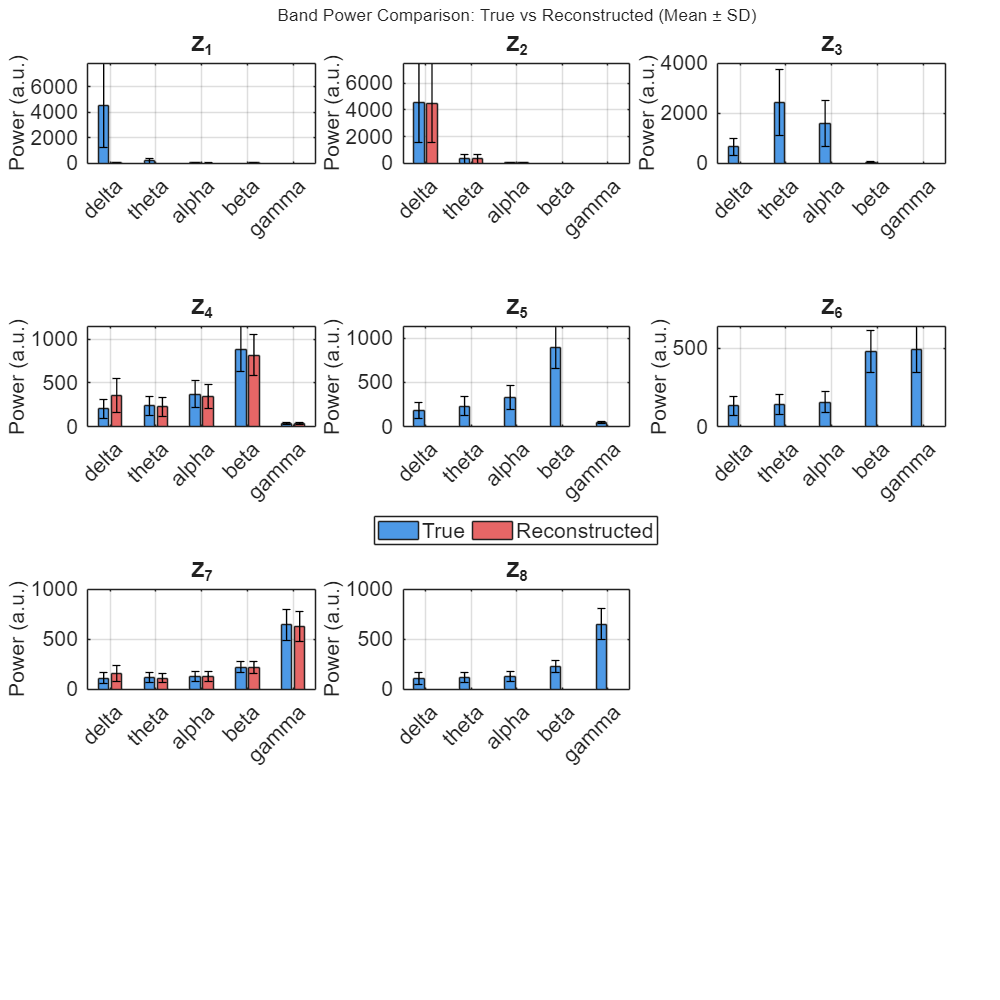

% --- Compute trial-averaged band power for true and reconstructed ---
band_power_true = zeros(nBands, size(h_f_normalized_ds,2));
band_power_recon = zeros(nBands, size(h_f_normalized_ds,2));
band_power_true_std = zeros(nBands, size(h_f_normalized_ds,2));
band_power_recon_std = zeros(nBands, size(h_f_normalized_ds,2));

for b = 1:nBands
    band = band_names{b};
    f_range = bands.(band);
    idx = f >= f_range(1) & f <= f_range(2);

    for fidx = 1:size(h_f_normalized_ds,2)
        % Compute trial-wise power (mean across band frequencies)
        trial_power_true = mean(abs(Ht_ae(idx,fidx,:)).^2, 1, 'omitnan');
        trial_power_recon = mean(abs(Hr_ae(idx,fidx,:)).^2, 1, 'omitnan');

        % Average across trials
        band_power_true(b,fidx) = mean(trial_power_true(:));
        band_power_recon(b,fidx) = mean(trial_power_recon(:));

        % Std across trials
        band_power_true_std(b,fidx) = std(trial_power_true(:));
        band_power_recon_std(b,fidx) = std(trial_power_recon(:));
    end
end

% --- Add new figure section for bar chart ---
figure('Position',[100 100 1000 250*floor(param.N_F/2)])
tiledlayout(floor(param.N_F/2), 3, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('Band Power Comparison: True vs Reconstructed (Mean ± SD)');

for fidx = 1:size(h_f_normalized_ds,2)
    nexttile
    % prepare data for grouped bars: [true; recon]
    bar_data = [band_power_true(:,fidx), band_power_recon(:,fidx)];
    bar_std = [band_power_true_std(:,fidx), band_power_recon_std(:,fidx)];
    bh = bar(bar_data); hold on

    % Add error bars
    ngroups = size(bar_data,1);
    nbars = size(bar_data,2);
    groupwidth = min(0.8, nbars/(nbars + 1.5));
    for i = 1:nbars
        % Calculate center of each bar
        x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
        errorbar(x, bar_data(:,i), bar_std(:,i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end

    % Style
    bh(1).FaceColor = [0.3 0.6 0.9]; % true
    bh(2).FaceColor = [0.9 0.4 0.4]; % recon
    ylabel('Power (a.u.)')
    set(gca, 'XTickLabel', band_names, 'XTickLabelRotation', 45)
    title(['Z_{' num2str(param.f_peak(fidx)) '}'])
    
    grid on
end
legend({'True','Reconstructed'}, 'Location','northoutside','Orientation','horizontal')
set(findall(gcf,'-property','FontSize'),'FontSize',16);

## 2.4.3.5 Spectral R^2 bar chart

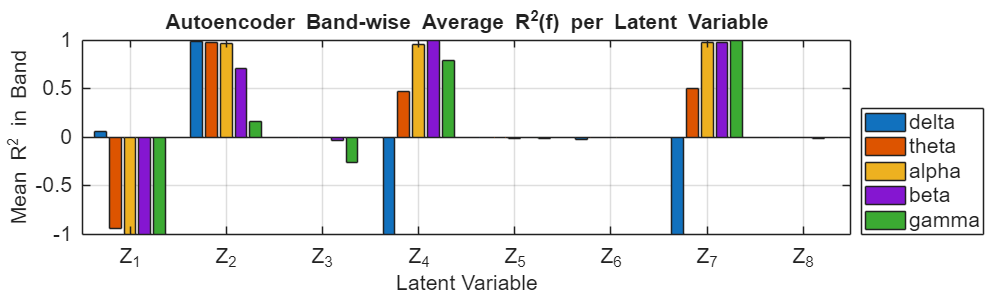

figure('Position',[50 50 1000 300])
tiledlayout(1, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
bar(band_avg_R2_ae');
set(gca, 'XTickLabel', arrayfun(@(i) sprintf('Z_{%d}',param.f_peak(i)), 1:param.N_F, 'UniformOutput', false));
ylim([-1 1]);
legend(band_names, 'Location', 'southeastoutside');
ylabel('Mean R^2 in Band');
xlabel('Latent Variable');
title('Autoencoder Band-wise Average R^2(f) per Latent Variable');
grid on;
set(findall(gcf,'-property','FontSize'),'FontSize',16);

## 2.4.3.6 R^2 Scatter plot: True vs Reconstructed Band Amplitudes

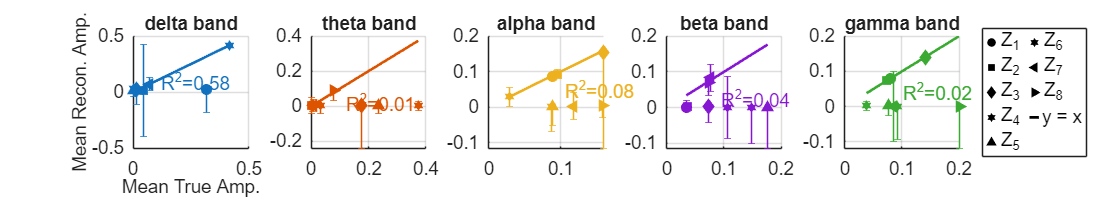

% Compute mean FFT amplitude in each band for true vs reconstructed latents

Ht_amp = abs(Ht_avg_ae(1:nHz, :));  % True latent mean amplitude spectrum
Hr_amp = abs(Hr_avg_ae(1:nHz, :));  % Reconstructed latent mean amplitude spectrum

% Normalizing amplitudes before comparison:
Ht_amp = Ht_amp ./ max(Ht_amp(:));
Hr_amp = Hr_amp ./ max(Hr_amp(:));

mean_band_amp_true  = zeros(nBands, size(h_f_normalized_ds,2));
mean_band_amp_recon = zeros(nBands, size(h_f_normalized_ds,2));
stdDev_band_amp_true  = zeros(nBands, size(h_f_normalized_ds,2));
stdDev_band_amp_recon = zeros(nBands, size(h_f_normalized_ds,2));

for b = 1:nBands
    band = band_names{b};
    f_range = bands.(band);
    idx_band = f_plot >= f_range(1) & f_plot <= f_range(2);

    % mean FFT amplitude within this frequency band
    mean_band_amp_true(b,:)  = mean(Ht_amp(idx_band,:), 1, 'omitnan');
    mean_band_amp_recon(b,:) = mean(Hr_amp(idx_band,:), 1, 'omitnan');
    
    % Standard Deviation FFT amplitudes
    stdDev_band_amp_true(b,:)  = std(Ht_amp(idx_band,:), 0, 1, 'omitnan');
    stdDev_band_amp_recon(b,:) = std(Hr_amp(idx_band,:), 0, 1, 'omitnan');
end

% Flatten across latents so each band has multiple data points
true_vals  = mean_band_amp_true(:);
recon_vals = mean_band_amp_recon(:);
band_labels = repelem(band_names, size(h_f_normalized_ds,2));

% --- Plot ---
figure('Position',[50 50 1600 300])
tiledlayout(1, param.N_F, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('True vs Reconstructed Band Mean FFT Amplitudes (per latent)');

colors = lines(nBands);
markers = {'o','s','d','h','^','hexagram','<','>'};
hold on;

for b = 1:nBands    
    nexttile;   
    idx_b = strcmp(band_labels, band_names{b});
    x = true_vals(idx_b);
    y = recon_vals(idx_b);
    
    for m = 1:length(markers)
        hold on;
        scatter(x(m), y(m), 70, 'filled', 'MarkerFaceColor', colors(b,:),'Marker', markers{m},...
            'DisplayName', [sprintf('Z_{%d}', param.f_peak(m))]);
        
        % Add error bars for standard deviations
        errorbar(x(m), y(m), stdDev_band_amp_true(b, m), stdDev_band_amp_recon(b, m), ...
                 'LineStyle', 'none', 'Color', colors(b,:), 'CapSize', 5,'HandleVisibility', 'off');
        %hold off;
    end

    % hold on;
    % linear regression fit
    p = polyfit(x, y, 1);
    xfit = linspace(min(x), max(x), 100);
    % yfit = polyval(p, xfit);
    yfit = xfit;
    plot(xfit, yfit, 'Color', colors(b,:), 'LineWidth', 2, 'DisplayName', "y=x");

    % optional: show R² of fit
    R_fit = corrcoef(x, y);
    R2_fit = R_fit(1,2)^2;
    text(mean(x), mean(y), sprintf('R^2=%.2f', R2_fit), 'Color', colors(b,:), 'FontSize', 12)
    if b==1
        xlabel('Mean True Amp.')
        ylabel('Mean Recon. Amp.')
    end

    title([ band_names{b} ' band'])
    % legend('Location','bestoutside')
    grid on;
    % axis equal;
    % hold off;
end

nLatents = length(markers);
% --- Build black proxy icons for legend ---
proxy_handles = gobjects(nLatents + 1,1);  % +1 for the y=x line

% One proxy per latent marker
for m = 1:nLatents
    proxy_handles(m) = scatter(nan, nan, 70, 'Marker', markers{m}, ...
                               'MarkerEdgeColor', 'k', ...
                               'MarkerFaceColor', 'k');
end

% Proxy for y=x line
proxy_handles(end) = plot(nan, nan, 'k', 'LineWidth', 2);

legend_labels = [arrayfun(@(m) sprintf('Z_{%d}', param.f_peak(m)), 1:length(markers), 'UniformOutput', false), ...
                 {'y = x'}];


legend(proxy_handles, legend_labels, 'Location','eastoutside','TextColor','k','IconColumnWidth',7, 'NumColumns',2);
hold off;
set(findall(gcf,'-property','FontSize'),'FontSize',14)

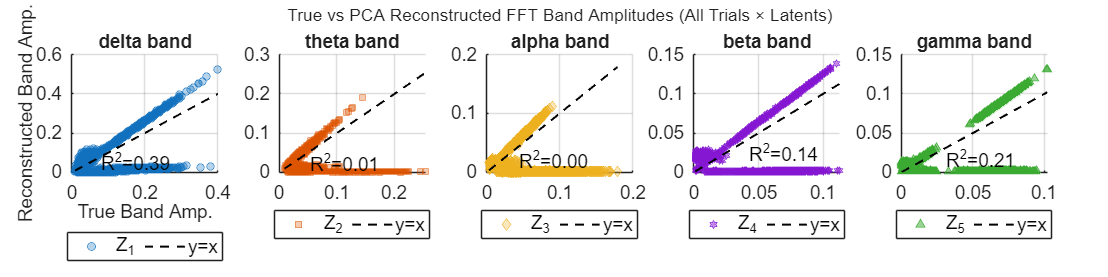

%% --- Scatter plot: True vs Reconstructed Band Amplitudes (per trial) ---

% Use trialwise FFT amplitude
Ht_amp_trials = abs(Ht_ae(1:nHz, :, :));   % [freq × latent × trial]
Hr_amp_trials = abs(Hr_ae(1:nHz, :, :));

% Normalize across everything exactly like before
Ht_amp_trials = Ht_amp_trials ./ max(Ht_amp_trials(:));
Hr_amp_trials = Hr_amp_trials ./ max(Hr_amp_trials(:));

% Containers for scatter data
true_vals_band  = cell(nBands, 1);
recon_vals_band = cell(nBands, 1);

for b = 1:nBands
    band = band_names{b};
    f_range = bands.(band);
    idx_band = f_plot >= f_range(1) & f_plot <= f_range(2);

    % Band-averaged amplitudes per trial, per latent
    % Size: [nLatent × nTrials]
    temp_true  = squeeze(mean(Ht_amp_trials(idx_band, :, :), 1, 'omitnan'));
    temp_recon = squeeze(mean(Hr_amp_trials(idx_band, :, :), 1, 'omitnan'));

    % Flatten latent × trial into one long vector of points
    true_vals_band{b}  = temp_true(:);
    recon_vals_band{b} = temp_recon(:);
end

%% ----------- PLOTTING -----------------
figure('Position',[50 50 1200 500])
tiledlayout(1, nBands, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('True vs PCA Reconstructed FFT Band Amplitudes (All Trials × Latents)');

colors = lines(nBands);
markers = {'o','s','d','h','^','hexagram','<','>'};

for b = 1:nBands
    nexttile;
    hold on;

    x = true_vals_band{b};
    y = recon_vals_band{b};

    % Scatter all trial points
    scatter(x, y, 30, 'Marker', markers{b}, ...
        'MarkerEdgeColor', colors(b,:), ...
        'MarkerFaceColor', colors(b,:), ...
        'MarkerFaceAlpha', 0.3, ...
        'DisplayName', [sprintf('Z_{%d}', param.f_peak(b))]);

    % Identity line
    xfit = linspace(min(x), max(x), 100);
    plot(xfit, xfit, 'k--', 'LineWidth', 1.5, 'DisplayName', 'y=x');

    % Regression R²
    R_fit = corrcoef(x, y);
    if numel(R_fit) > 1
        R2_fit = R_fit(1,2)^2;
        text(mean(x), mean(y), sprintf('R^2=%.2f', R2_fit), ...
            'Color', 'k', 'FontSize', 12);
    end

    title([band_names{b} ' band'])
    if b==1
        xlabel('True Band Amp.')
        ylabel('Reconstructed Band Amp.')
    end
    legend('Location','southoutside','TextColor','k','Orientation','horizontal');
    grid on;
end


set(findall(gcf,'-property','FontSize'),'FontSize',14)

## 2.5 Importing subject EEG

% --- paths (use your original logic) ---
if exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end

conditions = {'BLA'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load

## Load and import file as EEGLAB matrix

% Concatenate beta-band filtered data across conditions and trials:
% beta_concat = [];        % will be channels x totalSamples
trial_ranges = [];       % Nx2 start/end indices in concatenated samples
trial_info = {};         % optional: store [condition, trialIndexInCondition]

for ci = 1:numel(conditions)
    condition = conditions{ci};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    if isempty(set_files)
        fprintf('No .set files for %s — skipping\n', condition);
        continue
    end
    % load first subject/file (you used set_files(1).name)
    EEG = pop_loadset(fullfile(in_dir, set_files(1).name));
    if isempty(fs), fs = EEG.srate; end

    % choose odd/even indexing as in your pipeline
    if ismember(condition, {'BLA','P1','P2','P3'})
        epoch_trials = 1:2:EEG.trials;
    else
        epoch_trials = 2:2:EEG.trials;
    end

    data = EEG.data(:, :, epoch_trials); % channels x time x trials
    nTrials = size(data,3);
    nTime = size(data,2);

    % % preallocate and bandpass each epoch (Signal Processing Toolbox bandpass)
    % beta_band = [13 30];
    % beta_local = zeros(size(data));
    % for tr = 1:nTrials
    %     % bandpass expects samples x 1 or samples x channels -> transpose
    %     beta_local(:,:,tr) = bandpass(squeeze(data(:,:,tr))', beta_band, fs)'; 
    % end
    % 
    % % reshape: channels x (time * trials)
    % resh = reshape(beta_local, num_ch, nTime * nTrials);

    % % append to concatenated matrix
    % startIdx = size(beta_concat,2) + 1;
    % beta_concat = [beta_concat, resh];
    % endIdx = size(beta_concat,2);

    % % store trial boundaries (assumes contiguous blocks of length nTime)
    % for tr = 1:nTrials
    %     s = startIdx + (tr-1)*nTime;
    %     e = s + nTime - 1;
    %     trial_ranges = [trial_ranges; s e];
    %     trial_info{end+1} = struct('condition',condition,'trialInCond',tr);
    % end
end

pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


fprintf('EEG size: channels x samples = %d x %d\n x %d \n', size(data,1), size(data,2), size(data,3));

EEG size: channels x samples = 32 x 1792
 x 60 


## 2.5.1 Visualizing the EEG for the first trial

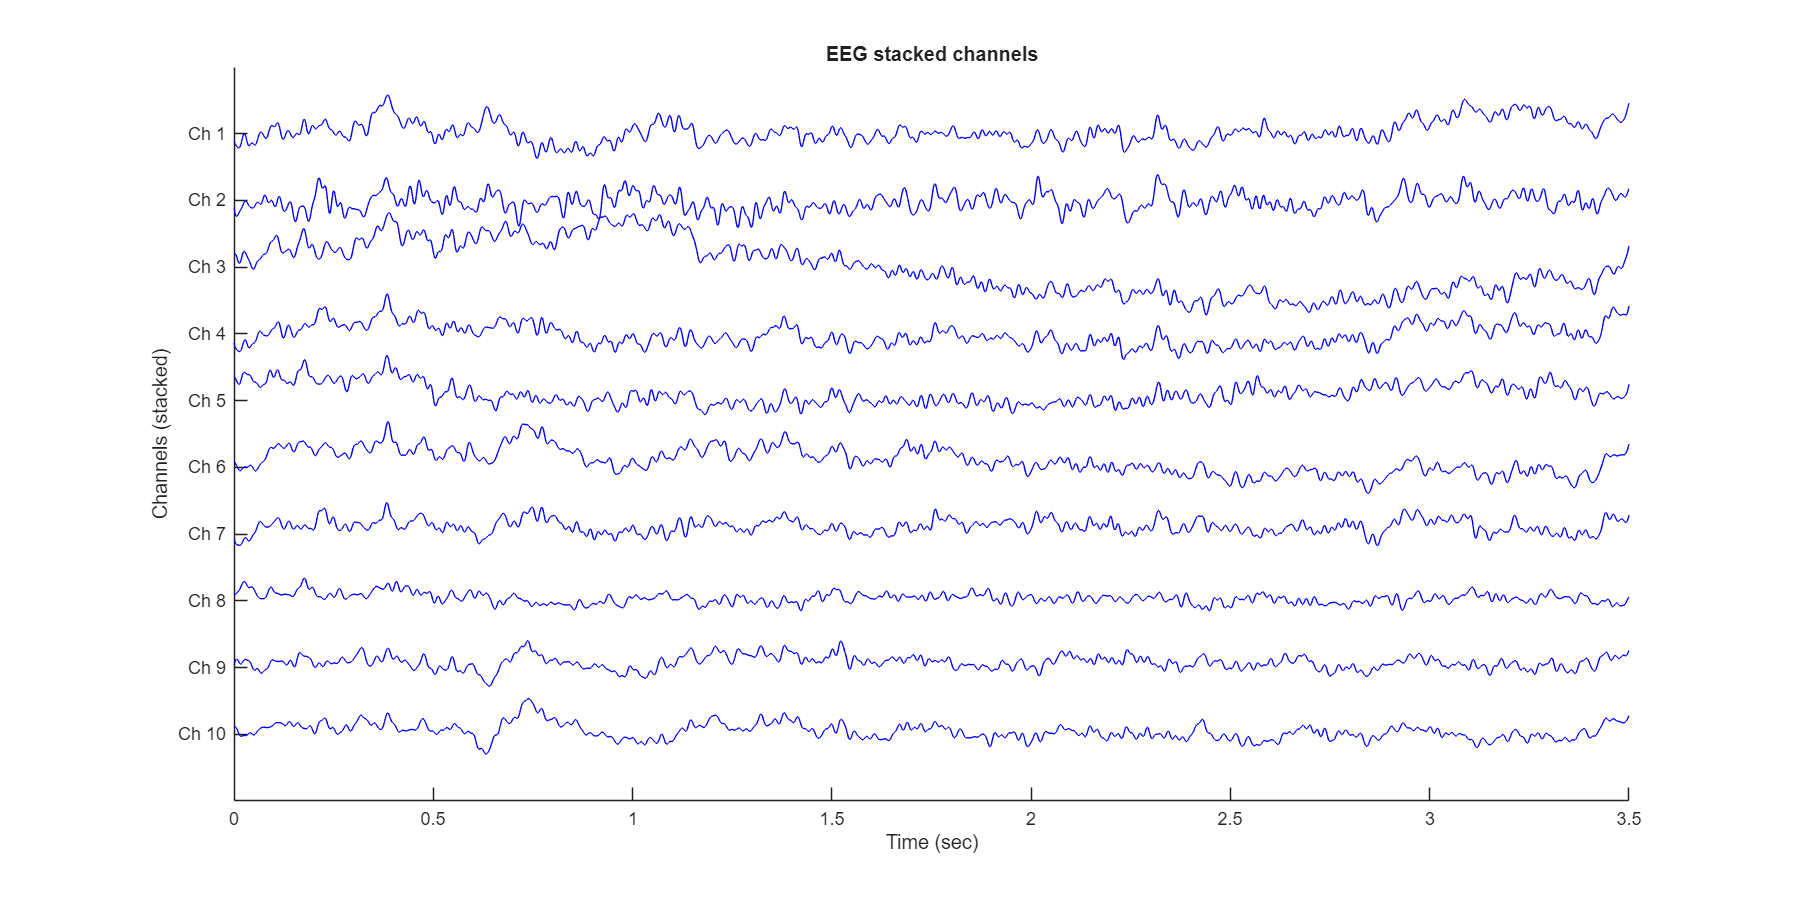

data_resh = reshape(data, num_ch, nTime * nTrials);
num_channels_plot = 10;
T_subject = 3.5; % duration of each trial

figure('Position',[50 50 1200 600])
% tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
offset = 30; % vertical spacing between channels
hold on
time_ms_eeg = linspace(0,T_subject,T_subject * EEG.srate); % time in milliseconds
for ch = 1:num_channels_plot
    % plot each channel stacked upward
    plot(time_ms_eeg, data_resh(ch+1,1:size(data,2),1) + (num_channels_plot - ch)*offset, 'b');
end
hold off

xlim([0 3.5]);
ylim([-offset, num_channels_plot*offset]);

xlabel('Time (sec)');
ylabel('Channels (stacked)');
yticks((0:num_channels_plot-1)*offset);
yticklabels(arrayfun(@(c) sprintf('Ch %d', num_channels_plot - c + 1), 1:num_channels_plot, 'UniformOutput', false));
title('EEG stacked channels');

## 2.5.2 Parameter setup for AE

X = data_resh;

batch_size = 80; %fs_orig
% batch_size = 256;
bottleNeck = 6;
T = size(X,2);

idx_split = floor(0.8*T);
X_subject_train = X(:,1:idx_split);
X_subject_test  = X(:,idx_split+1:end);

## 2.5.3 Run AE for subject data

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        31.69 |        30.69 |     502.0697 |     470.9793 |          0.0010 |
|       1 |          50 |       00:00:02 |        24.12 |              |     290.8508 |              |          0.0010 |
|       1 |         100 |       00:00:03 |        20.08 |              |     201.6595 |              |          0.0010 |
|       1 |         150 |       00:00:03 |        17.99 |              |     161.7382 |              |          0.0010 |
|       

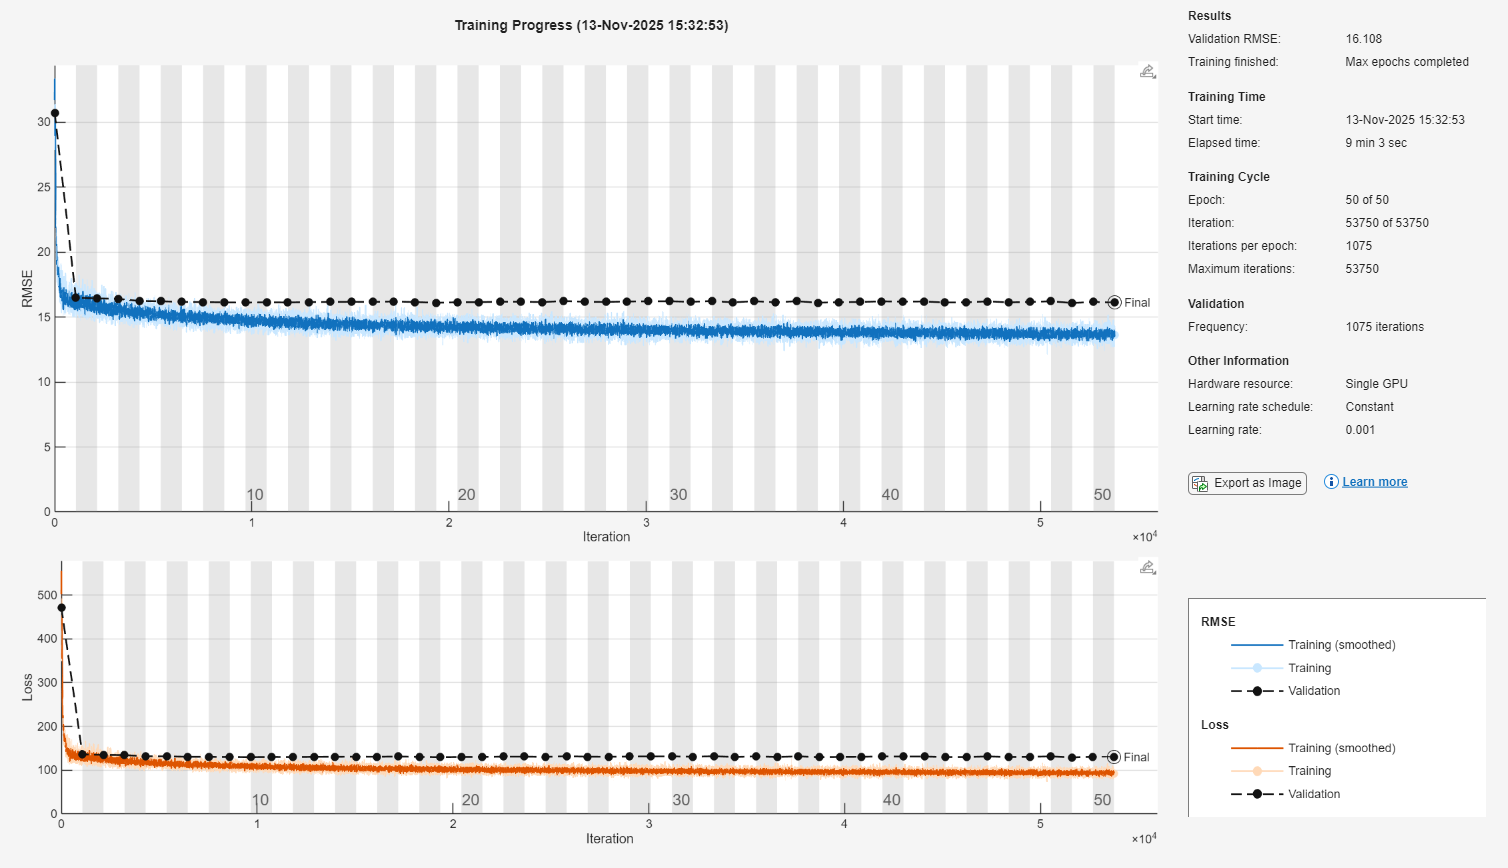

[net, info] = trainEEGAutoencoder(X_subject_train, X_subject_test,  ...
    'encoderLayerSizes', [64,32], ...
    'bottleneckSize', bottleNeck, ...
    'decoderLayerSizes', [32,64], ...
    'encoderActivations', {'relu','relu'}, ...
    'decoderActivations', {'relu','relu'}, ...
    'outputActivation', "none", ...
    'epochs', 50, ...
    'batchSize', batch_size, ...
    'learnRate', 1e-3);

## 2.5.4 Encode into latent space and getting the bottle neck variables

Z_train_subject = activations(net, X_subject_train.', 'bottleneck', 'OutputAs','rows');
Z_test_subject  = activations(net, X_subject_test.',  'bottleneck', 'OutputAs','rows');

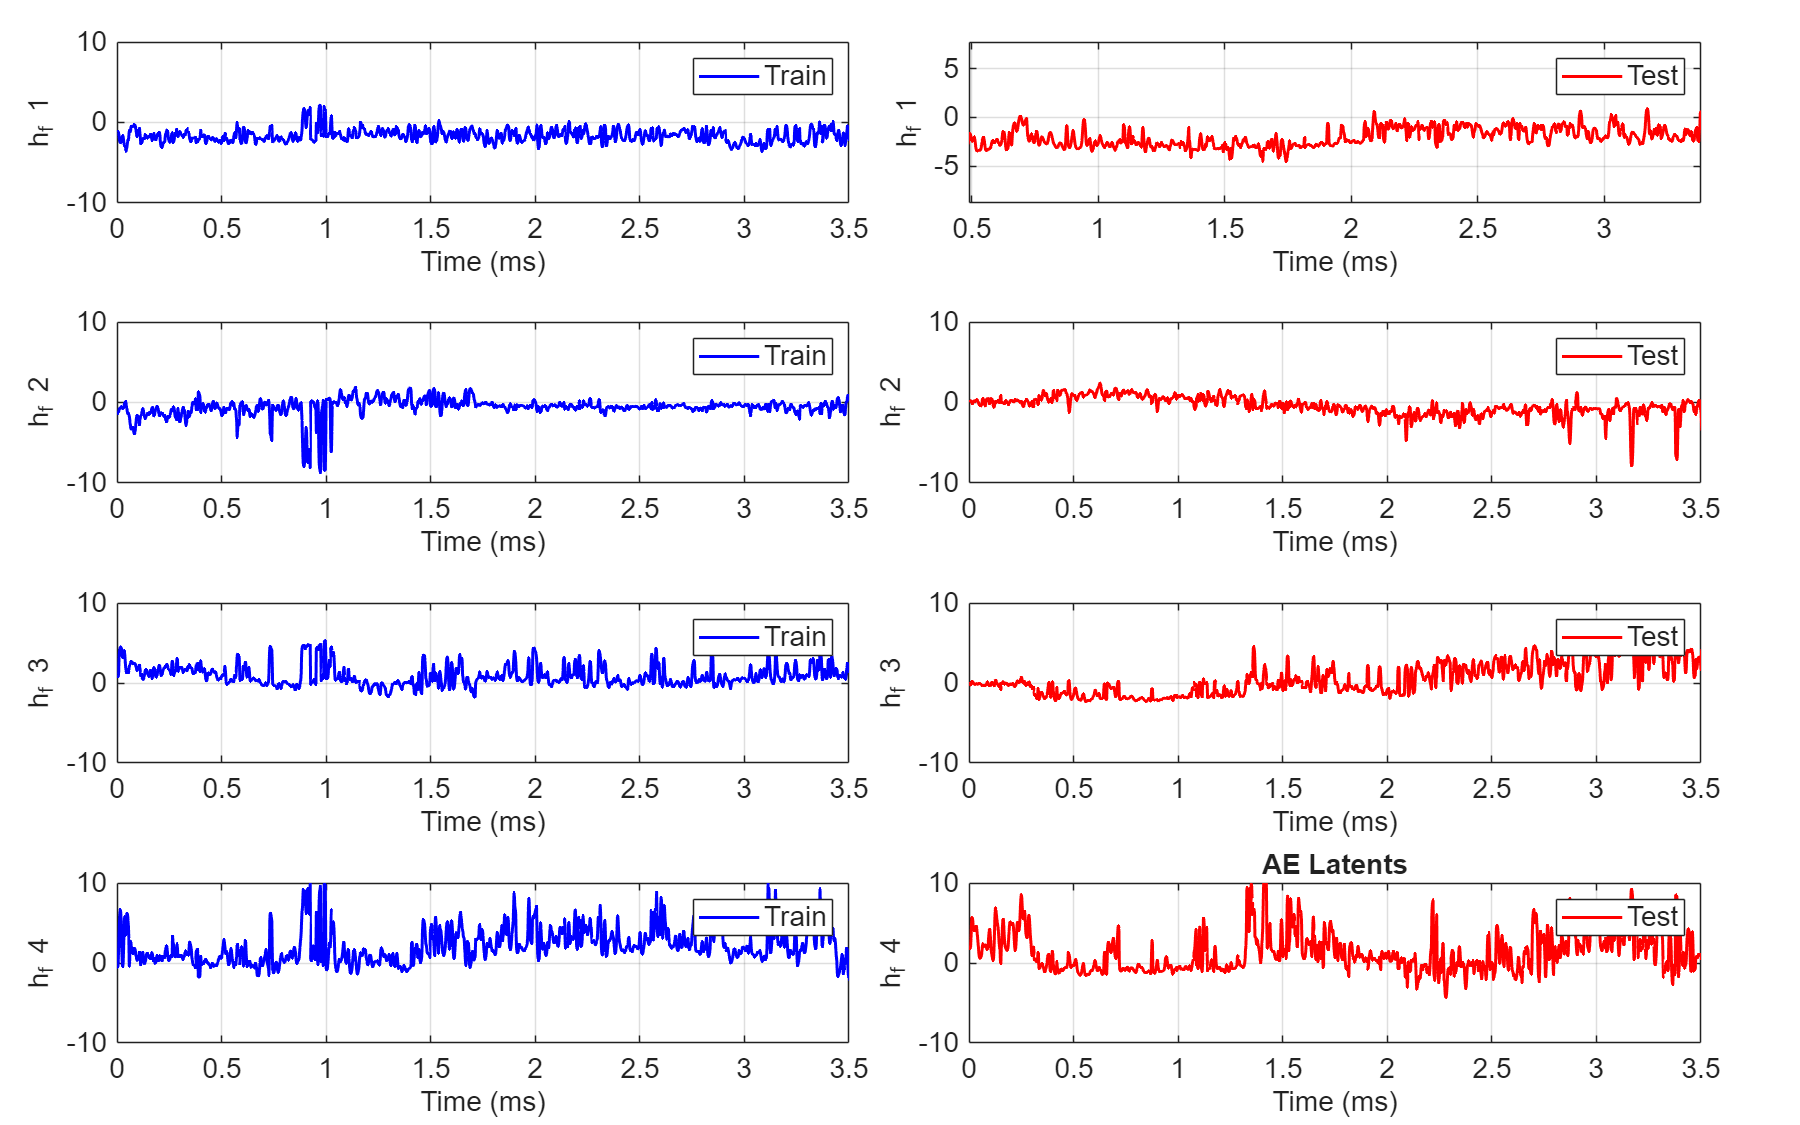

pred_H_train_s = hz_net(Z_train_subject.').';
pred_H_test_s  = hz_net(Z_test_subject.').';
num_latents = size(pred_H_train_s,2);
% Prepare figure
figure('Name','AE Subject Latents ', 'Position', [100, 100, 1200, 750]);
tiledlayout(num_latents, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for f = 1:num_latents
    % z_idx = matched_Z_idx(f);  % get the Z column corresponding to this h_f
    t_l_s = length(pred_H_train_s(:,1));
    t_l_s2 = length(pred_H_test_s(:,1));
    t_train = (1:t_l_s)/fs;
    t_test = (1:t_l_s2)/fs;
    nexttile;
    % plot(1:idx_split, H_train(:,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    plot(t_train, pred_H_train_s(:,f), '-', 'Color', 'b', 'LineWidth', 1.5);
    ylabel(sprintf('h_f {%d}', f));
    xlabel('Time (ms)');
    xlim([0 T_subject]);
    ylim([-10 10]);
    legend({'Train'});
    grid on;
    hold off;

    nexttile;
    % plot(1:t_l, H_test(:,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    plot(t_test, pred_H_test_s(:,f),      '-', 'Color', 'r', 'LineWidth', 1.5);
    ylabel(sprintf('h_f {%d}', f));
    xlabel('Time (ms)');
    xlim([0 T_subject]);
    ylim([-10 10]);
    legend({'Test'});
    grid on;
    hold off;
    
end

    %set(gca, 'XTickLabel', []);
title('AE Latents');
set(findall(gcf,'-property','FontSize'),'FontSize',14);

function [X_windows] = make_windows(X, winLen, hop)
% X: channels x time
% returns: windows as [nWindows x (channels*winLen)] rows for trainNetwork
[nCh, T] = size(X);
nWins = floor((T - winLen)/hop) + 1;
X_windows = zeros(nWins, nCh*winLen);
for w = 1:nWins
    idx = (w-1)*hop + (1:winLen);
    patch = X(:, idx);           % channels x winLen
    X_windows(w, :) = patch(:)'; % flatten (row)
end
end

function Xrec_full = overlap_add(Xrec_windows, h_f, winLen, hop_size)
    % overlap_add: reconstruct multichannel signal from overlapping windows
    %
    % Inputs:
    %   Xrec_windows - [nWindows × (nCh * winLen)] reconstructed segments
    %   h_f          - filter kernel (optional, or [] if none)
    %   winLen       - samples per window
    %   hop_size     - overlap step (default: winLen/2)
    %
    % Output:
    %   Xrec_full - reconstructed [nCh × totalTime] signal

    if nargin < 4
        hop_size = winLen / 2;
    end

    nWins = size(Xrec_windows, 1);
    nCh = size(h_f, 2);
    total_len = (nWins - 1) * hop_size + winLen;
    Xrec_full = zeros(nCh, total_len);

    % Go through each window
    for w = 1:nWins
        % Reshape flat window into [nCh × winLen]
        start_idx = (w - 1) * hop_size + 1;
        win = reshape(Xrec_windows(w,:), [nCh, winLen]);

        % If a filter kernel is provided, convolve each channel
        if ~isempty(h_f)
            for ch = 1:nCh
                conv_res = conv(win(ch,:), h_f(:,min(ch, size(h_f,2))));
                end_idx = start_idx + length(conv_res) - 1;
                Xrec_full(ch, start_idx:end_idx) = Xrec_full(ch, start_idx:end_idx) + conv_res;
            end
        else
            end_idx = start_idx + winLen - 1;
            Xrec_full(:, start_idx:end_idx) = Xrec_full(:, start_idx:end_idx) + win;
        end
    end

    % Normalize overlap regions (to prevent amplitude doubling)
    overlap_count = zeros(1, total_len);
    for w = 1:nWins
        start_idx = (w - 1) * hop_size + 1;
        end_idx = start_idx + winLen - 1;
        overlap_count(start_idx:end_idx) = overlap_count(start_idx:end_idx) + 1;
    end
    Xrec_full = Xrec_full ./ max(overlap_count, 1);
end